# Introduction to statistics for hypothesis testing

This Matlab livescript is intended to help explain statistical methods for hypothesis testing using code and examples (with minimal mathematics). It is restricted to univariate tests on continuous data, and focuses on issues that arise in neuroimaging, e.g, when there are multiple tests on topographically organised and smooth data. The code is written to aid comprehension, rather than for speed/efficiency. Some sections require having run code in preceding sections. It assumes basic knowledge of programming (eg. loops / functions / vectorisation). It was originally written for the MRC CBU's COGNESTIC Summer School, but can stand-alone.

It starts with sampling theory, central limit thoerem and randomisation testing, then proceeds to null hypothesis testing (error rate and power), focusing on T-tests and including Bayes Factors, then moves to the multiple comparison problem, height and cluster-level family-wise and false-disovery correction, before introducing the General Linear Model, ANOVAs, F-tests, error nonsphericity, error partitioning, multiple regression, timeseries, and finishes with Linear Mixed Effects models.

Any corrections/comments welcomed. Rik Henson, May 2024. rik.henson@mrc-cbu.cam.ac.uk. 

## Random Sampling

Let's assume we have data from a large population of people, where the values have a Gaussian distribution with mean of 0 and standard deviation (std) of 1 (a "unit normal" distribution). We will create this distribution explicitly below for the sake of comprehension (even though most programming languages allow you to draw randomly from such a distribution on the fly):

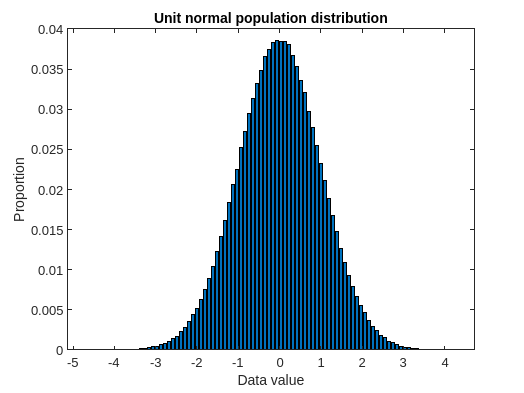

clear all
rng('default') % Initialise random seed
pop_size = 1e6; % Needs to be big (but not exceed RAM!)
pop_mean = 0; pop_std = 1;
pop = randn(pop_size,1)*pop_std + pop_mean; % Draw randomly from distribution
% since pop_size finite, re-centre (important if pop_size not big enough)
pop = (pop - mean(pop))/std(pop); % Reset to exactly unit normal ("Z-scoring")
pop = pop*pop_std + pop_mean; % re-set to desired std and mean
[pdf,vals] = hist(pop,100); pdf = pdf/pop_size; % plot histogram
figure,bar(vals,pdf),title('Unit normal population distribution')
xlabel('Data value'); ylabel('Proportion')

Let's pretend we don't know the mean of the population, but want to estimtate it by drawing a random (sub)sample from the population. 

samp_size = 1e2; % Sample size
select = ceil(rand(samp_size,1)*pop_size); % random subset of people from population
samp = pop(select); % their values
fprintf('Mean of one sample = %4.3f\n',mean(samp))

Mean of one sample = 0.050


We can make this process an inline function (technically, this is sampling with replacement, but when samp_size << pop_size, repeat sample values extremely unlikely, and this is faster than sampling without replacement):

sample_pop = @(pop,samp_size,num_samp) pop(ceil(rand(samp_size,num_samp)*length(pop)));

But of course there will be an uncertainty associated with any such estimate of the population mean from a smaller sample. We can see this by repeating the process many times, to get a new distribution of sample means:

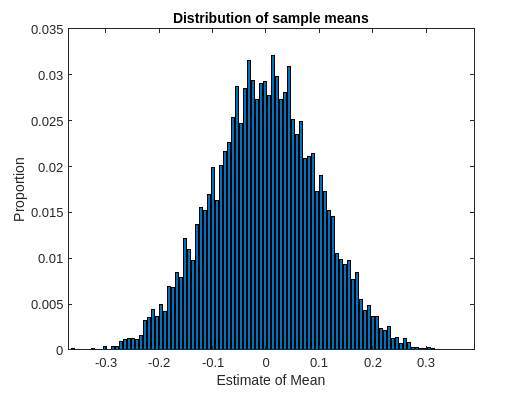

num_samp = 1e4; % Number of samples
samp = sample_pop(pop,samp_size,num_samp);
mean_vals = mean(samp);
[pdf,vals] = hist(mean_vals,100); pdf = pdf/num_samp;
figure,bar(vals,pdf),title('Distribution of sample means')
xlabel('Estimate of Mean'); ylabel('Proportion')

fprintf('Std of distribution of means of samples = %4.3f\n',std(mean_vals))

Std of distribution of means of samples = 0.100


### Central Limit Theorem

Note that the std of the distribution of mean estimates ("standard error of mean") is equal to the std of the population divided by the square-root of the sample size - something we will come back to later. Another thing worth noting about this distribution of mean estimates is that, with big enough sample size, it will approach a Gaussian distribution, even if the original population distribution is not Gaussian ("Central Limit Theorem"):

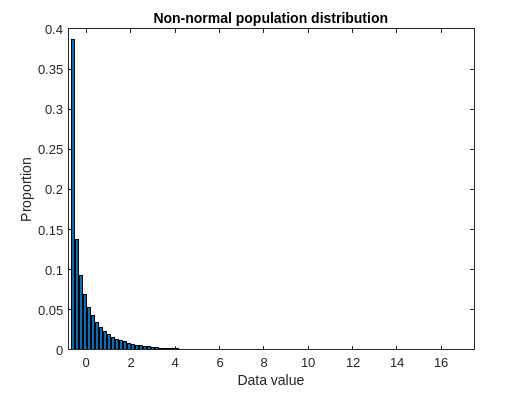

pop2 = pop.^2; % Create a positively skewed distribution
%pop3 = pop.^3; % Create a positively kurtotic distribution
pop2 = (pop2 - mean(pop2))/std(pop2); % Reset to have mean of 0 and std of 1 (if were Gaussian!)
[pdf,vals] = hist(pop2,100); pdf = pdf/pop_size;
figure,bar(vals,pdf),title('Non-normal population distribution')
xlabel('Data value'); ylabel('Proportion')

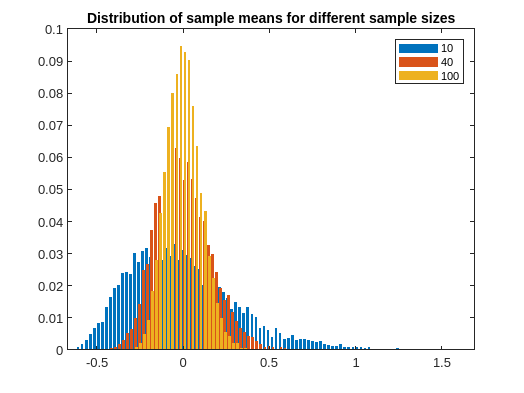


samp_size = [10 40 100]; % Explore range of sample sizes
mean_vals = nan(num_samp,length(samp_size));
for s = 1:length(samp_size)
    samp = sample_pop(pop2,samp_size(s),num_samp);
    mean_vals(:,s) = mean(samp)';
end
[pdf,vals] = hist(mean_vals,100); pdf = pdf/num_samp; figure,bar(vals,pdf,3)
title('Distribution of sample means for different sample sizes')
legend(compose('%d',samp_size))

Note that, not only does the spread of the distributions decrease as sample size increase, but the distributions become more Gaussian (e.g, the distribution from a sample size of 10 is still skewed, like the native population, but hardly skewed when sample size is 100).

### Randomisation (permutation) testing

Normally we only have one sample, and hence only one mean, so how do we know how likely it is that the population mean is greater than 0? One way to estimate the variability of our mean estimate is to re-sample randomly, but this time from our single sample (rather than the population). One approach is to select values randomly with replacement, which is called "bootstrapping". However, another way that is more appropriate for hypothesis testing is called "permutation testing" (sampling with replacement). For testing the mean of a single sample, permutation is equivalent to randomly switching the sign of each value in the sample (see later example of a paired T-test for justification). This is a type of randomisation test (also called a non-parametric test). If we repeat this a large number of times, we get an estimate of the distribution of the mean: 

samp_size = 100

samp_size = 100

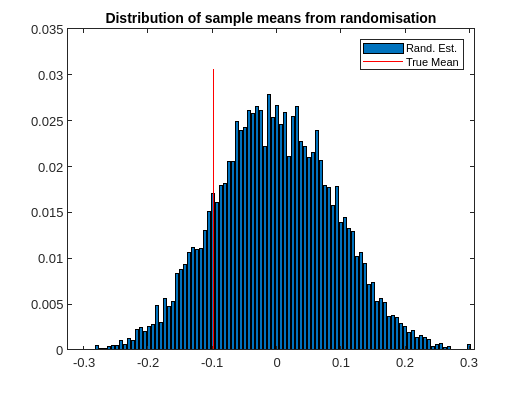

one_sample = sample_pop(pop,samp_size,1);
num_rand = 1e4; % Number of randomisations
mean_vals = nan(num_rand,1);
for r = 1:num_rand
    %resamp = one_sample(ceil(rand(samp_size,1)*samp_size)); % bootstrap sample with replacement
    resamp = one_sample.*sign(rand(samp_size,1)-0.5); % permutation sample with replacement
    mean_vals(r) = mean(resamp);
end
[pdf,vals] = hist(mean_vals,100); pdf = pdf/num_samp; figure, bar(vals,pdf)
true_mean = mean(one_sample);
hold on, line([true_mean true_mean]',[0 1.1*max(pdf)],'Color','r')
title('Distribution of sample means from randomisation')
legend({'Rand. Est.','True Mean'})

fprintf('Std of distribution of means from randomisation = %4.3f\n',std(mean_vals))

Std of distribution of means from randomisation = 0.092


Notice that the standard error of the mean is again close to expected value of pop_std/sqrt(samp_size). This randomised distribution can be used to calculate confidence intervals around the mean, e.g, the 95% confidence interval can be obtained by sorting the distribution from smallest to largest, and selecting the value just above the 95th percentile (assuming num_rand>100):

mean_vals = sort(mean_vals, 'ascend');
ci95 = mean_vals(floor(.95*length(mean_vals))+1);
fprintf('Sample mean is %4.3f with upper 95-percent confidence interval of %4.3f\n',true_mean,ci95);

Sample mean is -0.098 with upper 95-percent confidence interval of 0.149


Such confidence intervals are often obtained with boot-strapping, though for hypothesis testing, permutation is better (see next section).

## Hypothesis Testing

We can now have a first stab at hypothesis testing. In traditional "null hypothesis signficance testing" (NHST), to test our hypothesis that the mean of the population is greater than 0 (sometimes called the alternate hypothesis, H1), we strive to reject the null hypothesis (H0) that the mean of the population is zero. To test this with our sample, we can use the randomise_one_sample function given at end of script, which just uses the permutation code above (or other randomisation method) and returns the proportion of permuted means that are as big, or bigger, than the actual sample mean:

p_value = randomise_one_sample(one_sample);
fprintf('Proportion of randomised means greater than sample mean = %4.3f',p_value);

Proportion of randomised means greater than sample mean = 0.858

If we assume H0 is true (that population has mean of zero), and are also happy to assume it is symmetrical around this zero-mean, then any value sampled would be as likely to be positive as it would be negative, which is why the permuted sign test is valid 

Under H0, this proportion is equally likely to lie anywhere between 0 and 1. This proportion is an estimate of the "p-value":  the probablity of getting a statistic as larger or larger than a critical value, given that H0 is true. We generally want this p-value to be small, i.e. want minimal risk of falsely rejecting H0 when it is in fact true. This threshold is called "alpha" and is conventionally set at .05, ie 1 in 20 chance that we conclude the mean is not zero when it is in fact. This is also called the false positive rate (or "type I error" rate).  

*Interesting factoid: What is the origin of 0.05 for alpha? A story says that the statistician Sir Ronald Fisher was crossing a court of his Cambridge college when someone asked "What odds would you trust for something not happening by chance?". Apparently he replied "1 in 20", perhaps without intending that this should become scientific dogma (though 0.05 was also used in his publications).*

### False positive rate and power

To check that our test does control false positive rate (FPR), we can simulate drawing many samples from the population (eg. doing many experiments), and calculate the proportion of experiments that give a false positive:

alpha = 0.05

alpha = 0.0500

samp_size = 20  % more realistic for human psychological experiment?

samp_size = 200

num_samp = 1e4; % reduce if want to speed up, but fpr will be less precise
p_values = nan(num_samp,1);
for s = 1:num_samp
    samp = sample_pop(pop,samp_size,1); % Take sample from population
    p_values(s) = randomise_one_sample(samp,num_rand);
end
fpr = sum(p_values<alpha)/num_samp;
fprintf('Randomised (false) positive rate when population has zero-mean = %4.3f',fpr);

Randomised (false) positive rate when population has zero-mean = 0.047

This shows that our permutation test does ensure that only around 5% of experiments would produce a false positive. 

Note that the resolution of the estimated p-value depends on the number of random resamples. For example, if num_rand=1e2, then we could only estimate the p-value to 2 decimal places. In general, a minimum num_rand of 1e4 is recommended. However, p-value resolution can also be affected by the sample size if the samp_size is small. For example, if samp_size=10, there are 2^samp_size=1024 possible permutations for a one-sample test. Furthermore, the randomise_one_sample function below does not enumerate all such permutations - it randomly samples possible permutations - making it likely that the same permutation will be sampled more than once if the sample size is not large enough (proper statistical software does enumerate all (or a subset of num_rand) permutations if feasible, but not done here to save time). So be wary of randomised p-values if the sample size is less than log2(1e4) (though note that greater resolution can be achieved by parametric approximation to the randomised distribution, e.g, using "percentile" interpolation).

*Exercise: you can check robustness to non-Gaussian populations by replacing "pop" with "pop2" or "pop3" (for skewed or kurtotic distributions), or try "bootstrap" as the randomisation method (passing 'bootstrap' as the third argument randomise_one_sample). What do you find, particularly when reducing samp_size to ~10? (Note there are yet other randomisation methods like Jacknife (leave-one-out resampling), but these are beyond present scope.)*

But what if our hypothesis is true, and the population mean is great than 0? How often does our test detect this? This is called the "power" of a test (sometimes denoted as 1-beta, given a certain alpha). If we create a new population with mean of 0.5 (which corresponds to a Cohen's d effect size of 0.5, since Cohen's d is mean divided by std, and here std=1)

effect_size = 0.5;
pop_H1 = pop + effect_size;
num_samp = 1e4; % reduce if want to speed up, but tpr will be less precise
p_values = nan(num_samp,1);
for s = 1:num_samp
    samp = sample_pop(pop_H1,samp_size,1);
    p_values(s) = randomise_one_sample(samp,num_rand);
end
tpr = sum(p_values<alpha)/num_samp;
fprintf('Randomised (true) positive rate with population effect size %3.2f = %4.3f',effect_size,tpr);

Randomised (true) positive rate with population effect size 0.50 = 0.695

This is a power around 70% (normally we aim for >80%). Power increases with sample_size, as you will see later. 

Note that there are other classes of non-parametric tests that have analytic solutions, e.g, those that ignore the magnitude of values and use only their ranks (or even just their signs). These rank-based statistics test the null hypothesis that the median (rather than mean) is zero, but are not considered here. Note also that you do not have to permute the mean - you can permute many different summary statistics, such as the median, or the T-statistic (below), or even properties like the maximum or cluster extent (later).

## The T-test

Next though, we need to introduce the T-test. This test uses a T-statistic (sometimes called "Student's T") which is defined for one sample as the mean divided by the standard error of the mean:

onet = @(y) squeeze(mean(y)./(std(y)/sqrt(size(y,1))));

Some maths can show that, under certain assumptions (that the population is Gaussian), the T-values under H0 follow a distribution called the T-distribution, which depends also on the degrees of freedom (df). For this simple case of a one-sample test, the df = samp_size - 1 (the -1 because we have used one df in our data to estimate the mean). From this, we can calculate the (one-tailed; see later) probability of obtaining a value of T or higher:

T2p_higher = @(T,df) squeeze(1-tcdf(T,df));

T  = onet(one_sample);
df = samp_size - 1;
p  = 1-tcdf(T,df); % p-value (use "p" because now parametric)
fprintf('T(%d) = %3.2f, p = %4.3f\n',df,T,p);

T(19) = -1.06, p = 0.850


where "tcdf" is the cumultive density function for the T distribution (in Matlab stats toolbox). 

This is called a "parametric" test, because it depends on a parametric (here Gaussian) assumption about the distribution of the property under test (here the mean). According to the CLT shown earlier, this assumption is met when samp_size is large (in fact, when df very large, T-distribution becomes Gaussian, and the p-value is equivalent to that for the Z-statistic, Z = mean/std). For smaller samples, there are tests to determine whether the sample comes from a normal distribution (and hence assumption will be met that mean will also follow a normal distribution ), but ironically, the smaller the sample size (and hence bigger the risk that the assumption about distribution of mean is violated), the less sensitive these tests become.

*Interesting factoid: the "Student" in "Student's T-test" was the pseudonym of a statistician called Gosset, who worked for Guinness to quality control batches of beer, and used the pseudonym to avoid the ban of publishing research for commerical reasons.*

We can also check that the T-test controls the FPR and gives similar Power:

num_samp = 1e4; 
samp = sample_pop(pop, samp_size, num_samp); % Draw num_samp samples of samp_size
p    = T2p_higher(onet(samp), samp_size-1);
fpr  = sum(p<alpha)/num_samp;
fprintf('False positive rate for T-test when H0 true = %4.3f\n', fpr);

False positive rate for T-test when H0 true = 0.051



samp = sample_pop(pop_H1, samp_size, num_samp); 
p    = T2p_higher(onet(samp), samp_size-1);
tpr  = sum(p<alpha)/num_samp;
fprintf('True positive rate for T-test under H1 with effect size of %3.2f = %4.3f\n', effect_size, tpr);

True positive rate for T-test under H1 with effect size of 0.50 = 0.694


fprintf('(cf. for randomisation test above)');

(cf. for randomisation test above)

(note how much quicker this is than randomisation testing!). However, what happens when parametric assumptions not met? We can repeat but drawing small samples from a non-Gaussian population (eg the skewed "pop2"):

samp_size = 10 

samp_size = 10

samp = sample_pop(pop2, samp_size, num_samp); % Draw num_samp samples of samp_size
p    = T2p_higher(onet(samp), samp_size-1);
fpr  = sum(p<alpha)/num_samp;
fprintf('False positive rate for T-test when H0 true = %4.3f\n', fpr);

False positive rate for T-test when H0 true = 0.009


The first thing to note is that the FPR is now less than alpha, i.e., the T-test has become conservative. This means the test may be less sensitive, but at least has not increased FPR above an accepted rate (cf. permutation tests if you tried exercise above). 

So if this one-sample T-test is quite robust, even to small samples, you might wonder why we bother with permutation tests, given they are computationally expensive? (note that are situations in two-sample T-tests where it is capricious; see later). One reason is that randomisation is more general, in that we can calculate probabilities for properties other than the mean (such as the maximum; see later), which may not have a parametric (analytic) solution.

So far, we have been testing H1 that the mean is greate than 0. This is called a directional or "one-tailed" test. We can also perform a two-tailed test to ask whether the mean is simply different from 0, by using absolute value of T:

T2p_2tails = @(T,df) squeeze(1-tcdf(abs(T),df));

Because we are effectively doing two tests now, we can divide our alpha by 2 (a special case of the Bonferroni correction; see later). 

We can now calculate power curves for a two-tailed, one-sample T-test:

alpha_cor = alpha/2

alpha_cor = 0.0250

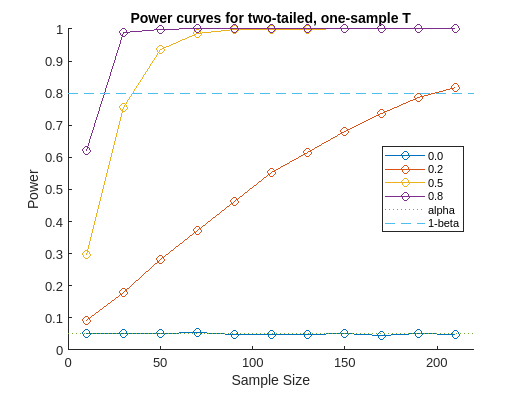

samp_sizes = [10:20:210];
effect_sizes = [0 0.2 0.5 0.8];
figure; hold on; title(sprintf('Power curves for two-tailed, one-sample T'))
pr = nan(length(samp_sizes),length(effect_sizes));
for es = 1:length(effect_sizes);
    pop_H1 = pop + effect_sizes(es);
    for s = 1:length(samp_sizes)
        samp = sample_pop(pop_H1, samp_sizes(s), num_samp);
        p = T2p_2tails(onet(samp),samp_sizes(s)-1);
        pr(s,es) = sum(p<alpha_cor)/num_samp;
    end
end
plot(samp_sizes,pr,'o-');
line([0 max(samp_sizes)+10],[alpha alpha],'LineStyle',':');
line([0 max(samp_sizes)+10],[.8 .8],'LineStyle','--');
txt = compose('%2.1f',effect_sizes); txt{end+1} = 'alpha';  txt{end+1} = '1-beta';
legend(txt,'Location','East')
axis([min(samp_sizes)-10 max(samp_sizes)+10 0 1])
xlabel('Sample Size'); ylabel('Power')

So for what Cohen called a "medium" effect size of 0.5, you now need a sample size of ~30 for 80% power (more than earlier because now two-tailed), but for what he called a "small" effect of 0.2, you need around 200.

## Bayes Factors

The above classical or "frequentist" statistics estimate the likelihood of getting a statistic larger than that obtained from the data, given that the null hypothesis is true. One consequence of this is that, if this p-value does not fall below our alpha, then we cannot reject H0, but nor can we accept it ("absence of evidence is not evidence of absence"). A Bayes Factor (BF) on the other hand is the ratio of two likelihoods: the probability of exceeding that statistic value if H1 is true, relative to the same probability if H0 is true (often called BF10; while its reciprocal is BF01). A high BF10 (e.g, 6 or 10; a matter of convention like alpha) would constitute evidence for H1, whereas a high BF01 (low BF10) would constitute evidence for the null. Being able to claim support for H0 is a major strength of BFs (there are other philosophical differences that are beyond the present remit).

The problem with calculating a BF however is specifying H1 precisely. This means not just an effect size (which could be based on previous studies for example), but also the precise distribution of the effect. The nice thing about NHST is that scientists can generally agree that an effect of exactly 0 is a reasonable null, but with BFs, they also have to agree on H1. To estimate the likelihood under H1, one needs to impose some priors, and if scientists use different priors, they could come to different conclusions.

One solution called "participantive priors" is to use priors that come from previous data or simulations or theory. While other scientists might disagree with these, they can at least be specified in advance, ideally with agreement from independent reviewers (eg in a Study Registration). An alternative is to stick with "objective priors", i.e, default priors that do not differ by experiment, and which the community agrees in advance (e.g, default priors for a Bayesian T-test). (A third option is "empirical priors", which arise when we have heirarhical models, as mentioned later).

To calculate the likelihood of getting a statistic (here the mean) under H0 and H1, we need to parametrise its prior distribution under H0 and H1. The likelihood is then estimated by integrating over all possible values of these parameters (so-called "marginalisation").

For H0, this is easy, because the prior corresponds to a delta function at 0. So the likelihood is just the likelihood of getting the actual mean given the standard error of the mean. Under assumption of a Gaussian distribution of population, this is given by the normal probability density function (PDF):

likelihood_data = @(y,mu) normpdf(mean(y), mu, std(y)/sqrt(length(y)));
samp = sample_pop(pop,1e2,1); % a random sample of 100 from unit normal
likelihood_mean_H0 = likelihood_data(samp,0); % Likelihood of mean under H0

(where likelihood is relative to integral of PDF). If we also assume a Gaussian distribution for H1, then this is fully described by two parameters: its mean and std. Here we assume the H1 mean is 0 (like H0), but by allowing a non-zero std (unlike H0), we allow for mean values different from zero. Indeed, the higher this H1 prior std, the more likely are means further from zero. If we can agree on a std (eg 0.5), then the likelihood under H1 is given by integrating over all possible values of the mean generated by this prior distirbution:

H1_mean = 0; H1_std = 0.5;
prior = @(x) normpdf(x, H1_mean, H1_std);
marginal = @(x,y) likelihood_data(y,x) .* prior(x);
likelihood_mean_H1 = integral(@(x) marginal(x,samp), -Inf, Inf);

BF10 is then just the ratio of these likelihoods:

BF10 = likelihood_mean_H1/likelihood_mean_H0

BF10 = 0.8560

which will tend to be <1, since the data were sampled from a zero-mean population, so BF should favour H0. Note there are other types of BF, for example based on the T-statistic rather than mean, and which use more sophisticated assumptions about the distributions of the mean and std, which are beyond present scope (such as the JZS prior common as the "objective prior" for a T-test). 

The above process is implemented in the function "one_sample_BF" at end of this script. We can plot BFs as a function of the effect size in the data and the variability in the mean allowed by H1:

effect_sizes = [0 0.2 0.4 0.6]; % effect sizes in data
H1_mean = [0 0 0]; H1_std = [0.2 0.4 0.6]; % variability under H1
num_samp = 1e3;
samp_size = 1e2

samp_size = 100

BF10_thr = 3

BF10_thr = 3

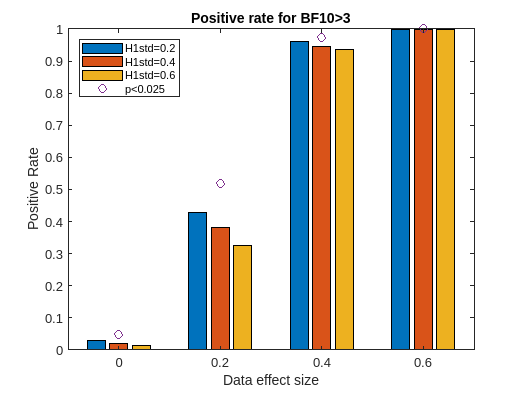

pr = nan(length(effect_sizes),length(H1_std)+1); % positive rate for BF10>thr
nr = pr; % negative rate for BF01>thr (BF10<1/thr)
for es = 1:length(effect_sizes)
    pop_H1 = pop + effect_sizes(es);
    samp = sample_pop(pop_H1,samp_size,num_samp);
    p = T2p_2tails(onet(samp),samp_size-1);
    BF10 = nan(num_samp,length(H1_std));
    for h1 = 1:length(H1_std)
        for s = 1:num_samp
            BF10(s,h1) = one_sample_BF(samp(:,s),H1_std(h1),H1_mean(h1));
        end
    end
    pr(es,1)     = sum(p<alpha_cor)/num_samp;
    pr(es,2:end) = sum(BF10 > BF10_thr)/num_samp;
    nr(es,2:end) = sum(BF10 < 1/BF10_thr)/num_samp;
end

txt = {}; for h1 = 1:length(H1_std); txt{h1} = sprintf('H1std=%2.1f',H1_std(h1)); end
txt{end+1} = sprintf('p<%4.3f',alpha_cor);
figure, bar(effect_sizes,pr(:,2:end)), title(sprintf('Positive rate for BF10>%d',BF10_thr))
hold on, plot(effect_sizes,pr(:,1),'o'), axis([-0.1 0.7 0 1])
legend(txt,'Location','NorthWest')
set(gca,'XTick',effect_sizes)
ylabel('Positive Rate'), xlabel('Data effect size')

Note that thresholding BFs in the above manner leads to the NHST notion of (false) positive rates, and many Bayesians prefer to keep only the BF as a continuous estimate of how much one should update their beliefs given the data (or prefer to focus on the posterior distributions of the parameters themselves, which is beyond present remit). Nonetheless, this plot shows comparable false positives when no effect (in this particular case), and when the effect size is greater than 0, power for BF approach increases the tighter the prior assumption. More important however is the positive rate when the BF favours H0:

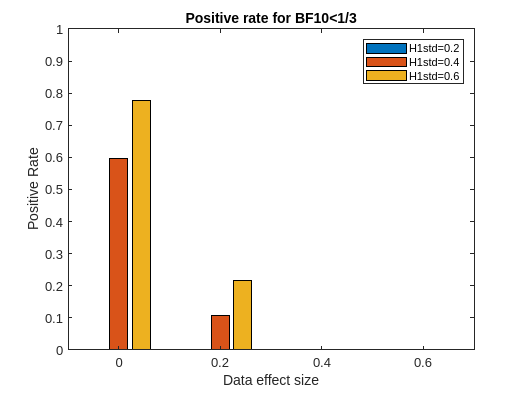

figure, bar(effect_sizes,nr(:,2:end)), title(sprintf('Positive rate for BF10<1/%d',BF10_thr))
legend(txt{1:(end-1)},'Location','NorthEast'), axis([-0.1 0.7 0 1])
set(gca,'XTick',effect_sizes)
ylabel('Positive Rate'), xlabel('Data effect size')

This is not something we can calculate with a p-value (though classical "equivalence tests" perform a similar function), but with the BFs, we have a reasonable chance of concluding that the evidence favours the null when the null is true (effect size is 0). Note that there is also some chance that we will support H0 when the true effect size is non-zero, but smaller than we expected (i.e, when H1std>0.2). This is not necessarily unreasonable. In other words, BFs are sensitive to the size of the effect; not just whether it is present (non-zero) or absent (zero).

*Exercise: what happens if you set prior mean of H1 to be >0, eg H1_mean = 0.6? You should see more cases when H0 is favoured when data mean is less than 0.6 (particularly when H1 std is small, ie when we have more precise expectations that effect should be 0.6) - why?*

Another advantage of using BFs is they naturally allow sequential designs, where we keep collecting more data until our BF threshold (for H1 or H0) is exceeded, which can be more efficient on average (at risk of slight increase in false positives). Nonethless, we return to the currently more conventional frequentist p-values for the rest of this script (where there is at least less room for debate about priors).

## Multiple Comparisons (correcting for many tests)

Sometimes we have multiple hypotheses that we wish to test. This is common in neuroimaging, eg for an ERP from a single channel, where we might have a 100 time points, or a 3D MRI image of 100x100x100 voxels. We'll only consider the 1D case here, with "num_tests" samples, though the arguments generalise to more than one dimension. So our data will now be a 3D matrix of sample_size (eg, number of participants) by num_tests (eg, number of voxels) by num_samp (number of experiments), which we're going to call "y".

Let's start by assuming that each test is independent, and H0 is true for all tests. We now wish to control the "family-wise error rate" (FWE) of at least one false positive across *all the tests* (to be less than alpha):

samp_size = 20

samp_size = 20

num_tests = 50

num_tests = 50

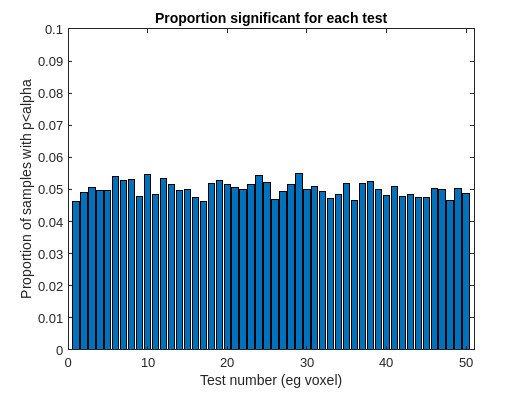

num_samp = 1e4;
y = nan(samp_size,num_tests,num_samp);
p = nan(num_tests,num_samp);
for s = 1:num_samp
    samp     = sample_pop(pop,samp_size,num_tests);
    y(:,:,s) = samp; % store for below
    p(:,s)   = T2p_higher(onet(samp),samp_size-1);
end
sig = (p < alpha);
figure,bar(sum(sig,2)/num_samp), title('Proportion significant for each test')
axis([0 num_tests+1 0 0.1])
xlabel('Test number (eg voxel)'); ylabel('Proportion of samples with p<alpha')

fprintf('Family-wise error rate = %4.3f\n',sum(any(sig,1))/num_samp)

Family-wise error rate = 0.921


Although the FPR in each test is around 0.05, the FWE much higher (i.e, likely that at least one test significant every time). One solution is to use scale our threshold by the number of tests - so-called "Bonferonni" correction:

alpha_cor = alpha/num_tests % Bonferonni

alpha_cor = 1.0000e-03

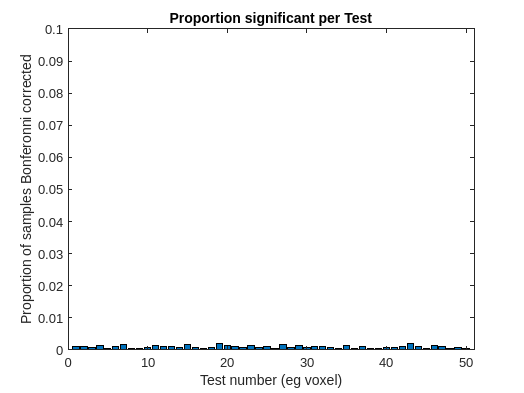

sig = (p < alpha_cor);
figure,bar(sum(sig,2)/num_samp), title('Proportion significant per Test')
axis([0 num_tests+1 0 0.1])
xlabel('Test number (eg voxel)'); ylabel('Proportion of samples Bonferonni corrected')

fprintf('Family-wise error rate = %4.3f\n',sum(any(sig,1))/num_samp)

Family-wise error rate = 0.048


*Interesting factoid: Carlo Bonferonni was a keen climber of glaciers, but we don't know whether he corrected his chance of death by the number of his climbs.*

This does control FWE at 5%. But in imaging, our tests are rarely indpeendent. For example, ERP data are temporally autocorrelated across time, while MRI voxels are typically correlated across space. We can simulate this by smoothing our data (here with a simple, moving average of all values within a smooth_window for speed purposes):

smooth_window = 20

smooth_window = 20

smooth_y = nan(size(y));
for s = 1:num_samp
    for p = 1:samp_size
        smooth_y(p,:,s) = smooth(squeeze(y(p,:,s)),smooth_window);
    end
end

In this case, Bonferronni correction is too conservative:

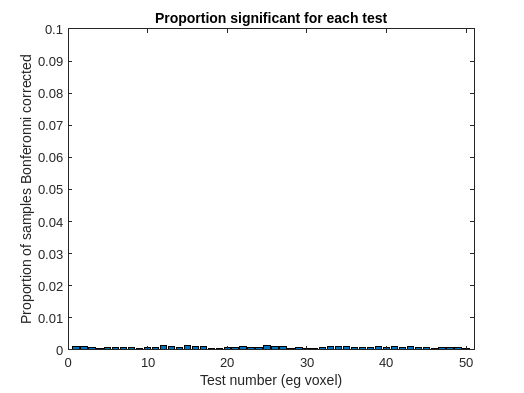

T   = onet(smooth_y);
p   = T2p_higher(T,samp_size-1);
sig = (p < alpha_cor);
figure,bar(sum(sig,2)/num_samp), title('Proportion significant for each test')
axis([0 num_tests+1 0 0.1])
xlabel('Test number (eg voxel)'); ylabel('Proportion of samples Bonferonni corrected')

fprintf('Family-wise error rate = %4.3f\n',sum(any(sig,1))/num_samp)

Family-wise error rate = 0.021


### Permuting maximal statistics

Fortunately, permutation tests come in useful here. It turns out that if we calculate the maximum T-value across tests, and its null distribution from permuting the data many times, then the (1-alpha) percentile of this distribution of maxTs provides a threshold that controls FWE at alpha, as demonstrated below:

y1 = squeeze(smooth_y(:,:,1)); % Calculate max T thr from one sample (experiment) for speed
num_rand = 1e4;
maxT_null = nan(num_rand,1);
for r = 1:num_rand
    rs = sign(rand(samp_size,1)-0.5);
    ry = y1 .* repmat(rs,[1 num_tests]); % must use same randomisation for all participants
    rT = onet(ry);
    maxT_null(r) = max(rT,[],2);
end
maxT_null = sort(maxT_null,'ascend');
maxT_thr  = maxT_null(floor((1-alpha)*num_rand)+1)

maxT_thr = 3.2145

(This is the basis of the "permute_maxT_one_sample" function at end of this script; note that it is important that each permutation is used for all voxels). Given this threshold for T-values, we can confirm the FWE is around .05: 

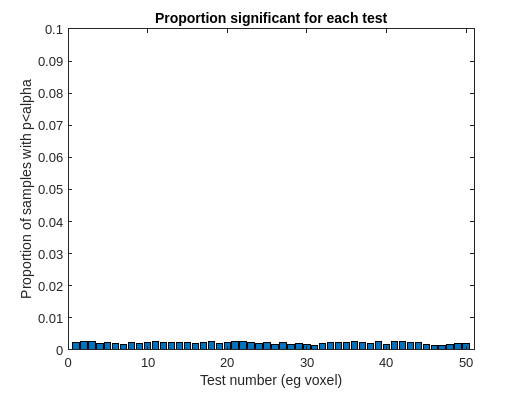

sig = (T > maxT_thr);
figure,bar(sum(sig,2)/num_samp), title('Proportion significant for each test')
axis([0 num_tests+1 0 0.1])
xlabel('Test number (eg voxel)'); ylabel('Proportion of samples with p<alpha')

fprintf('Family-wise error rate = %4.3f\n',sum(any(sig,1))/num_samp)

Family-wise error rate = 0.047


Note that one should calculate maxT_thr for each new dataset (experiment), but since our simulated experiments are identical, it is quicker to approximate this threshold for one dataset and apply to all experiments (cf. cluster size below).

We can now repeat for the unsmoothed case, confirming we still maintain FWE:

y1 = squeeze(y(:,:,1)); % Take first experiment to calculate Tthr
maxT_thr = permute_maxT_one_sample(y1)

maxT_thr = 3.5741

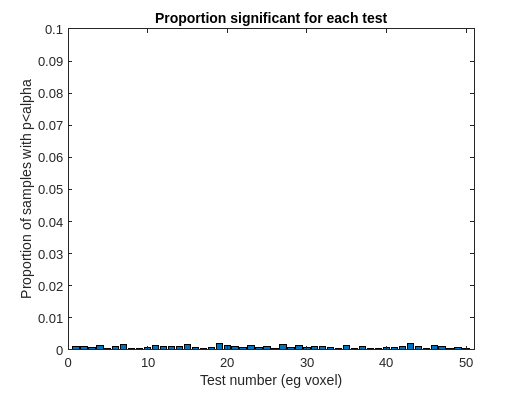

T = onet(y);
sig = (T > maxT_thr);
figure,bar(sum(sig,2)/num_samp), title('Proportion significant for each test')
axis([0 num_tests+1 0 0.1])
xlabel('Test number (eg voxel)'); ylabel('Proportion of samples with p<alpha')

fprintf('Family-wise error rate = %4.3f\n',sum(any(sig,1))/num_samp)

Family-wise error rate = 0.049


Now let's add some signal (to the original unsmoothed data). If consider the tests as voxels in a 1D image for the moment, let's assume a large but "localised" effect for voxel 30, plus a smaller but "distributed" effect across voxels 10:20:

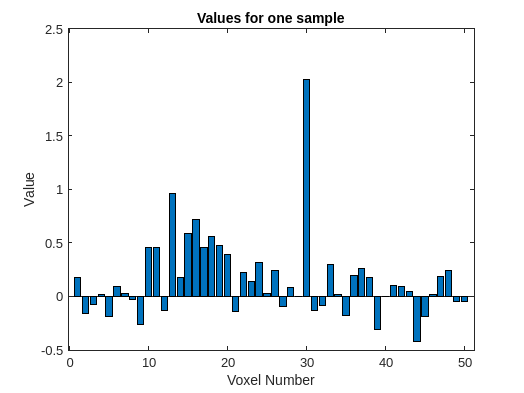

y_signal = y;
y_signal(:,30,:)    = y(:,30,:) + 2;
y_signal(:,10:20,:) = y(:,10:20,:) + 0.5;
y1 = squeeze(y_signal(:,:,1)); % Select example sample (first will do)
figure,bar(mean(y1)), title('Values for one sample'), xlabel('Voxel Number'), ylabel('Value')

Let's see what the positive rates look like over lots of experiments:

maxT_thr = permute_maxT_one_sample(y1)

maxT_thr = 3.5424

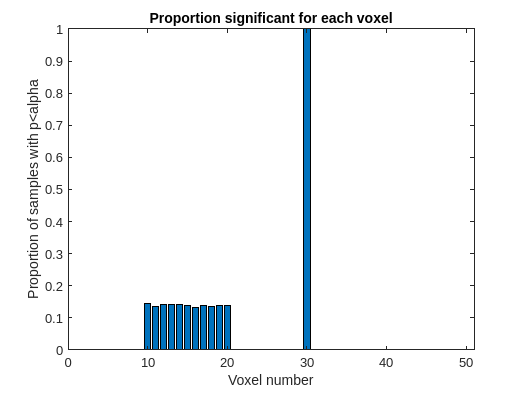

T = onet(y_signal);
sig = (T > maxT_thr);
figure,bar(sum(sig,2)/num_samp), title('Proportion significant for each voxel')
axis([0 num_tests+1 0 1]) % Note increase in y-axis scale
xlabel('Voxel number'); ylabel('Proportion of samples with p<alpha')

fprintf('Family-wise positive rate = %4.3f\n',sum(any(sig,1))/num_samp)

Family-wise positive rate = 1.000


We can detect the localised activation most of the time, but not the diffuse activation. One solution to the latter is to smooth the data, chosing a smoothing window that matches the extent of the diffuse cluster:

smooth_window = 10

smooth_window = 10

smooth_y_signal = nan(size(y_signal));
for s = 1:num_samp
    for p = 1:samp_size
        smooth_y_signal(p,:,s) = smooth(squeeze(y_signal(p,:,s)),smooth_window);
    end
end

Note that data may be intrinsically smooth, but we often want to explicitly smooth. One reason for this is to help justify the parametric assumptions of T-test, because smoothing effectively increases the amount of data being averaged, and so  benefits from the CLT.

So what happens when we apply same maximum T threshold to the smoothed data:

y1 = squeeze(smooth_y_signal(:,:,1));
maxT_thr = permute_maxT_one_sample(y1)

maxT_thr = 3.3463

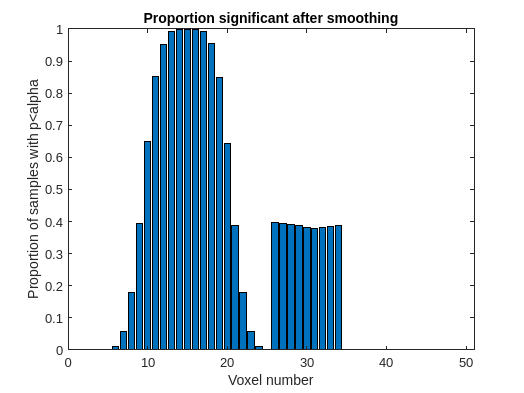

T = onet(smooth_y_signal);
sig = (T > maxT_thr);
figure,bar(sum(sig,2)/num_samp), title('Proportion significant after smoothing')
axis([0 num_tests+1 0 1]) % Note increase in y-axis scale
xlabel('Voxel number'); ylabel('Proportion of samples with p<alpha')

fprintf('Family-wise positive rate = %4.3f\n',sum(any(sig,1))/num_samp)

Family-wise positive rate = 1.000


You will notice that, while the power to detect voxels in the diffuse cluster has increased, that for the localised voxel has decreased, and its signal has in fact been smoothed into nearby voxels.

*Exercise: compare results with a smaller (eg 5) or bigger (eg 20) smoothing window (kernel) - do the results support the "matched filter theorem"?*

### Cluster-level Correction

But can we avoid "blurring" the data by smoothing, and still detect diffuse signals? Here permutation testing again helps us, because rather than permuting the maximal T value (which is suitable for detecting whether a single voxel is significant, sometimes called "peak" or "height" thresholding), we could permute the "cluster extent" - ie the number of contiguous voxels above some initial threshold. 

We first need to determine the cluster size after an initial thresholding of voxels, and label each voxel with the size of the cluster in which it sits. This is done by the function "label_with_cluster_size" at end below, but here is an example:

y1 = squeeze(mean(y_signal,3)); % mean of many samples of unsmoothed
cluster_defining_Tval = tinv(1-alpha, samp_size-1) % initial threshold to define clusters

cluster_defining_Tval = 1.7291

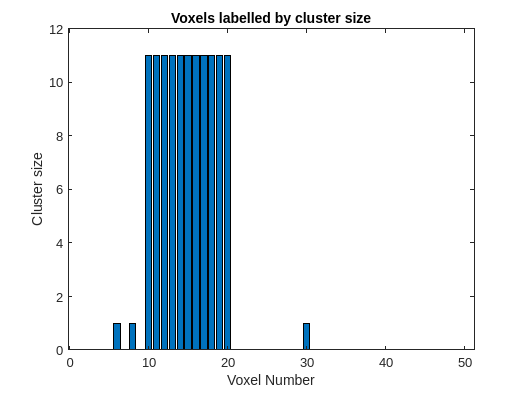

cs = label_with_cluster_size(onet(y1), cluster_defining_Tval);
figure,bar(cs), title('Voxels labelled by cluster size'), xlabel('Voxel Number'), ylabel('Cluster size')

Note that the diffuse cluster is labelled with true size of 11 (because we have averaged out most of noise by averaging across many experiments), as is size of 1 for local activation (plus few false positives). We can now estimate the distribution of maximal cluster size: 

y1 = squeeze(y_signal(:,:,1));
cs_null = nan(num_rand,1);
for r = 1:num_rand
    rs = sign(rand(samp_size,1)-0.5);
    ry = y1 .* repmat(rs,[1 num_tests]); % must use same randomisation for all tests
    rT = onet(ry);
    cs_null(r) = max(label_with_cluster_size(rT, cluster_defining_Tval));
end
cs_null = sort(cs_null,'ascend');
cs_thr  = cs_null(floor((1-alpha)*num_rand)+1);
fprintf('Minimum extent for cluster-level FWE correction: %d\n', cs_thr)

Minimum extent for cluster-level FWE correction: 2


This is called "cluster-level correction" (and is the basis of the "permute_cluster_metric_one_sample" function at end). Thus clusters of at least 2 voxels are unlikely by chance. Note that the initial threshold (here the T-value corresponding to p<.05 uncorrected) will affect extent threshold.

Note that there are parametric versions that correct FWE for peak or cluster extent using "Random Field Theory" but they are beyond scope here, and make more assumptions, such as requiring data to have a minimal smoothness, and a sufficiently stringent initial threshold for defining cluster size.

With only 50 voxels and hence small range of cluster sizes, we need to lower the cluster-defining threshold to get sufficient range of cluster sizes. Also, it is again more accurate to calculate the cs_thr for each sample (experiment), but for purposes of speed, we estimate from the first sample only:  

%num_samp = 1e4; % reduce if need to speed up
cluster_defining_Tval = 0.5 % initial cluster-defining height threshold

cluster_defining_Tval = 0.5000

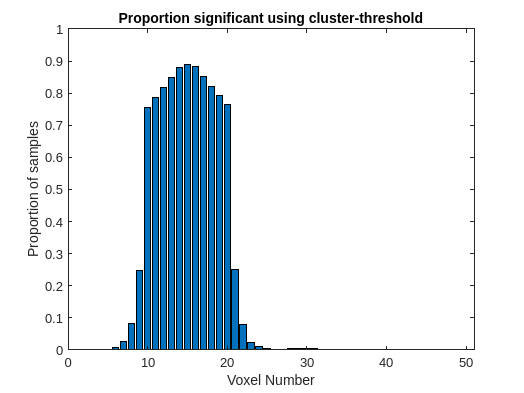

cs = nan(num_samp,num_tests); cs_thr = [];
for s = 1:num_samp
    ys = squeeze(y_signal(:,:,s));
    if s==1 % Faster to estimate from one sample, since all samples equivalent, and CS_thr relatively stable
        cs_thr = permute_cluster_metric_one_sample(ys,cluster_defining_Tval,alpha,num_rand,'size');
%        else
%            cs_thr(end+1) = permute_cluster_metric_one_sample(ys,cluster_defining_Tval,alpha,num_rand,'size');
    end
    T = onet(ys);
    cs(s,:) = label_with_cluster_size(T,cluster_defining_Tval);
    cs(s,:) = (cs(s,:) > cs_thr(end));
end
figure,bar(sum(cs)/num_samp), title('Proportion significant using cluster-threshold')
xlabel('Voxel Number'), ylabel('Proportion of samples'), axis([0 num_tests+1 0 1])

fprintf('Family-wise positive rate using Cluster-threshold = %4.3f\n',sum(any(cs,2))/num_samp)

Family-wise positive rate using Cluster-threshold = 0.899


Notice that the diffuse cluster is now detected reasonably well, but the localised one is not (cf. the case for corrected peak threshold earlier). We are basically trading-off statistical sensitivity for localising power: with the cluster-level correction, we are more sensitive (to clusters), but are unable to localise within clusters (ie cannot claim a particular voxel within a cluster is significant). 

*Exercise: Here we have applied to the unsmoothed data with signal, but you can see what happens for the smoothed data, smooth_y_signal, or the unsmoothed data with no signal, y (to check FWE), and what happens as you change the initial cluster-defining height threshold. You an also compare results when threshold calculated for each sample separately (by uncommenting lines above), and examine range of extent thresholds resulting (cs_thr), but it will take a long time...*

### Threshold-free Cluster Enhancement

Finally, one could permute a property that includes a contribution from both the height and extent of each cluster, such as the cluster "mass" (e.g, the product of height and extent of each cluster in the current 1D example). Note also that the results from the above cluster-level correction still depend on the initial height threshold that defines the clusters. A popular method that combines these ideas is the "Threshold-free Cluster Enhancement" (TFCE), which integrates the cluster masses across a range of thresholds, and is implemented in the "label_with_cluster_TFCE" function at end (with also allows different weightings of height and extent).

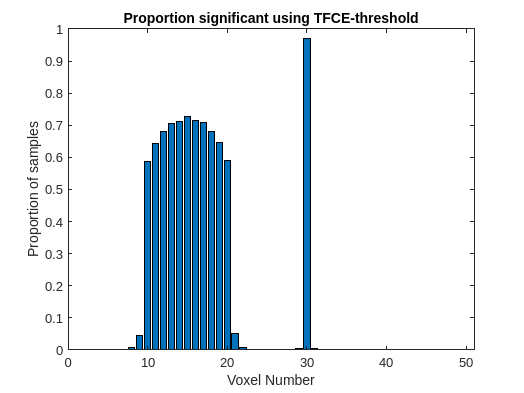

cm = nan(num_samp,num_tests); cm_thr = []; % cm = cluster mass
for s = 1:num_samp
    ys = squeeze(y_signal(:,:,s));
    T = onet(ys);
    thrs = prctile(T,[60:10:90]); % range of height thresholds to integrate over
    if s==1 % Faster to estimate from one sample, though TFCE threshold quite variable
        cm_thr = permute_cluster_metric_one_sample(ys,thrs,alpha,num_rand,'TFCE');
%        else
%            cm_thr(end+1) = permute_cluster_metric_one_sample(ys,thrs,alpha,num_rand,'TFCE');
    end
    cm(s,:) = label_with_cluster_TFCE(T,thrs);
    cm(s,:) = (cm(s,:) > cm_thr(end));
end
figure,bar(sum(cm)/num_samp), title('Proportion significant using TFCE-threshold')
xlabel('Voxel Number'), ylabel('Proportion of samples'), axis([0 num_tests+1 0 1])

fprintf('Family-wise positive rate using TFCE-threshold = %4.3f\n',sum(any(cm,2))/num_samp)

Family-wise positive rate using TFCE-threshold = 1.000


Now we are detecting both the diffuse activation and the localised activation with reasonable power. Note that, unlike the cs_thr above, the TFCE threshold varies quite a lot with the data.

### False Discovery Rate

Another common correction for multiple comparisons is not to control the FWE, but rather something called the False Discovery Rate (FDR). In the "Benjamini-Hochberg" version of FDR, the p-values are sorted from smallest to largest, and checked against thresholds with decreasing levels of correction, and then all p-values up to the largest that survives this threshold are declared significant ("discoveries"). 

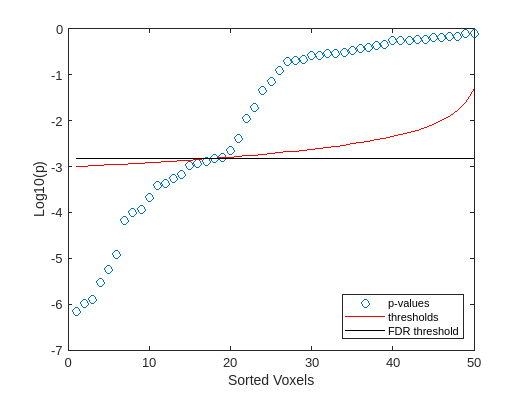

y1  = squeeze(smooth_y_signal(:,:,1)); % Select one sample for illustration
T   = onet(y1);
p   = T2p_higher(onet(y1),samp_size-1);
thr = alpha./[num_tests:-1:1];
ps  = sort(p,'ascend');
st  = find(ps < thr);
figure,plot(log10(ps),'o'); hold on; ylabel('Log10(p)'), xlabel('Sorted Voxels')
plot([1:num_tests], log10(thr),'r-') 
line([1 num_tests], [1 1]*log10(thr(max(st))), 'Color','k')
legend({'p-values', 'thresholds','FDR threshold'},'Location','SouthEast')

FDR is compared with FWE in the example below, where signal is put in first 40 voxels but not remaining 10: 

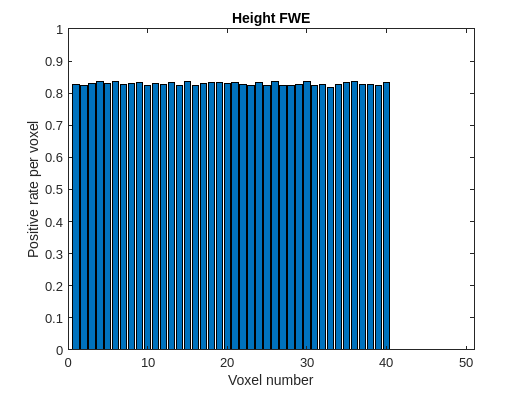

y_signal = y;
y_signal(:,[1:40],:) = y_signal(:,[1:40],:) + 1; % Add signal to first 25 voxels
% FWE
y1  = squeeze(y_signal(:,:,1)); % Select one sample max T threshold estimation
maxT_thr = permute_maxT_one_sample(y1);
T = onet(y_signal);
sig = (T > maxT_thr);
figure,bar(sum(sig,2)/num_samp), title('Height FWE')
axis([0 num_tests+1 0 1])
xlabel('Voxel number'); ylabel('Positive rate per voxel')

fprintf('Mean error rate in non-active voxels = %4.3f\n',mean(sum(sig(41:end,:),2)/num_samp))

Mean error rate in non-active voxels = 0.001


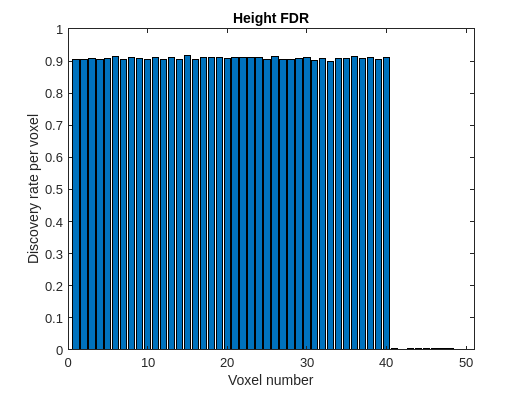

% FDR
p   = T2p_higher(T,samp_size-1);
sig = zeros(num_tests,num_samp);
for s = 1:num_samp
    [ps,ind] = sort(p(:,s),'ascend');
    st = find(ps' < thr);
    sig(ind(1:max(st)),s) = 1;
end
figure,bar(sum(sig,2)/num_samp), title('Height FDR')
axis([0 num_tests+1 0 1])
xlabel('Voxel number'); ylabel('Discovery rate per voxel')

fprintf('Mean error rate in non-active voxels = %4.3f\n',mean(sum(sig(41:end,:),2)/num_samp))

Mean error rate in non-active voxels = 0.004


Note FDR leads to more true positives for first 40 voxels. However, this comes at the cost of increased false positives in non-active voxels (the remaining 10 voxels). This is because FDR controls the number of false positives as a proportion (eg 5%) of voxels declared significant, rather than as a proportion of tests performed (like FWE). So the more active voxels there are in one part of the image, the more false positives there are likely to be in other parts of the image where there is no signal. Thus it is really a qualitatively different type of inference, and some would argue that maintaining the traditional FWE is more important.

Finally, note that all the methods above are designed for (safe) inferences on "mass univariate" tests. This is appropriate if the aim is localisation in space or time, but if the aim is to detect signal anywhere, note that there are much more sensitive "multivariate" tests like PLS/CCA that leverage on covariance between tests.

## Two-sample Tests

We now turn to two-sample tests. Here H0 is that the means of (whatever generated) two samples are equal. We start with the easy case of a "paired" test, where two "conditions" are measured on same people, i.e., each person contributes two values (sometimes called a "repeated measure"). In this case, we can simply calculate the difference between these two values for each person, and run a one-sample test on these "difference scores". In the context of a permutation test, we would be randomly swapping the two values for each person, hence the basis for randomising the sign of the (difference) values in the one-sample test examples above.

More interesting is the "unpaired" (or "independent samples") case, when the samples (groups) are drawn from two populations of different people, and we have one value per person. Under H0 that these populations are identical, we could randomly assign people to either group. This is called "exchangeability"; in the unpaired case, all values are exchangeable, whereas in the paired case, only values within the same person are exchangeable (exchangeability is normally a condition of randomisation tests). If there are N1 people in sample of first population, and N2 in second sample, then for a permutation test, there (N1+N2)!/(N1!N2!) permutations, which quickly gets very large as N1 and/or N2 increase. Nonetheless, it is normally sufficient to sample num_rand~1e4 to estimate a p-value, as done in the function "randomise_two_samples" function at end. 

Alternatively, we can also use a parametric approach, There are several versions of the parametric version of the two-sample T-test, but we can start with the simplest where:

twot = @(y) (mean(y{1}) - mean(y{2})) ./ sqrt(var(y{1})/size(y{1},1) + var(y{2})/size(y{2},1));

The numerator is the difference of means, while the denominator is the (sqrt of) the weighted sum of the variances of the two groups (this is an "unpooled" estimate of the standard error of the difference in means; later we introduce the "pooled" estimate). The p-value can then be calculated from the same T-distribution with dfs equal to the total number of people minus 2 (used for estimating mean within each group).

Assuming equal group sizes, we can plot power curves for two-tailed, unpaired T-tests as a function of group sizes:

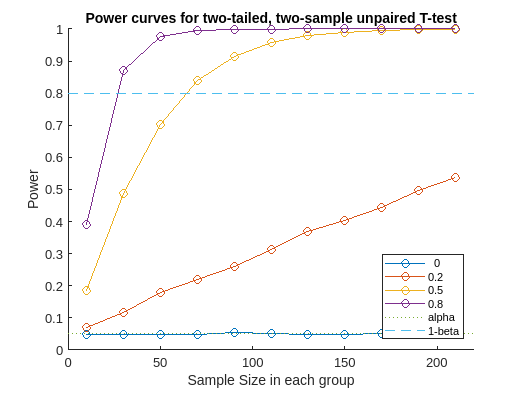

alpha_cor    = alpha/2; % Two-tailed
samp_sizes   = [10:20:210]; % Number of participants per group
effect_sizes = [0 0.2 0.5 0.8]';
figure; hold on; title(sprintf('Power curves for two-tailed, two-sample unpaired T-test'))
pr = nan(length(samp_sizes),length(effect_sizes));
y = cell(1,2);
for es = 1:length(effect_sizes)
    pop_H1 = pop + effect_sizes(es);
    for s = 1:length(samp_sizes)
        df = 2*samp_sizes(s)-2;
        y{1} = sample_pop(pop_H1, samp_sizes(s), num_samp);
        y{2} = sample_pop(pop, samp_sizes(s), num_samp);
        p = T2p_2tails(twot(y),df);
        pr(s,es) = squeeze(sum(p < alpha_cor)/num_samp);
    end
end
plot(samp_sizes,pr,'o-');
line([0 max(samp_sizes)+10],[alpha alpha],'LineStyle',':');
line([0 max(samp_sizes)+10],[.8 .8],'LineStyle','--');
txt = cellstr(num2str(effect_sizes)); txt{end+1} = 'alpha';  txt{end+1} = '1-beta';
legend(txt,'Location','SouthEast')
axis([min(samp_sizes)-10 max(samp_sizes)+10 0 1])
xlabel('Sample Size in each group'); ylabel('Power')

Note that groups of at ~70 are needed to get 80% power with a medium effect size, which means testing 140 people in total. This is quite a bit more than the ~30 needed for a paired T-test (equivalent to the one-sample T-test above). This demonstrates the increased power of repeated measures designs. Note also that many  imaging studies use relatively small samples of ~20 per group, which would entail power of only ~30%.

*Exercise: Calculate power curves after controlling FWE across a large number of tests. Imagine for example you have an fMRI study with 1e6 voxels (and no a priori ideas where you might find an effect): even allowing for an intrinsic smoothness in the data (such that you might only have 1e3 "resels" - "resolvable elements" - for Bonferonni correction), what are chances of traditional fMRI group sizes finding a true effect somewhere in the brain while controlling FWE?*

### Unequal group sizes and pooled variance estimates

We can also plot what happens when the total number of participants is fixed, but the ratio of group sizes varies:

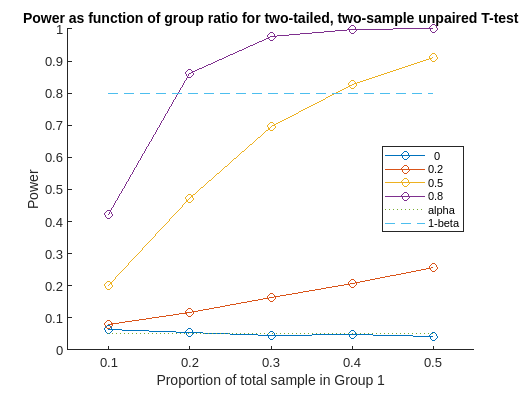

totsamp_size = 50;
df = totsamp_size - 2;
group_ratio = [0.1:0.1:0.5]; % max 0.5
figure; hold on; title(sprintf('Power as function of group ratio for two-tailed, two-sample unpaired T-test'))
pr = nan(length(group_ratio),length(effect_sizes));
y = cell(1,2);
for es = 1:length(effect_sizes);
    pop_H1 = pop + effect_sizes(es);
    for s = 1:length(group_ratio)
        samp_size(1) = round(group_ratio(s)*totsamp_size);
        samp_size(2) = totsamp_size - samp_size(1);
        y{1} = sample_pop(pop_H1, samp_sizes(s), num_samp);
        y{2} = sample_pop(pop,    samp_sizes(s), num_samp);
        p = T2p_2tails(twot(y),df);
        pr(s,es) = squeeze(sum(p < alpha_cor)/num_samp);
    end
end
plot(group_ratio,pr,'o-');
line(group_ratio([1 end]),[alpha alpha],'LineStyle',':');
line(group_ratio([1 end]),[.8 .8],'LineStyle','--');
txt = cellstr(num2str(effect_sizes)); txt{end+1} = 'alpha';  txt{end+1} = '1-beta';
legend(txt,'Location','East')
axis([0.05 0.55 0 1])
xlabel('Proportion of total sample in Group 1'); ylabel('Power')

The first thing to note is that power decreases as the groups become more unbalanced. However, more problematic is that the FPR exceeds alpha for the most unbalanced case (when Group 1 only has 5 participants for example). This reflects the fact that estimates of variance become very noisy with small sample sizes, and the unpooled T-test gives equal weight to each group. Indeed, the unpooled T-test is undefined if a group only contains one person.

One solution is to weight the estimate of variance towards the larger group, equivalent to a "pooled" T-test (also equivalent to GLM formalism below). This works even if one group has only one participant (sometimes called Crawford's T-test). This is implemented in the more general function "two_sample_T" at end. 

### Inhomogeniety of variance: correcting dfs (Welch)

However even variance pooling fails when the variance of one group differs from the other, which is an important assumption of the standard T-test. Such "inhomogeniety" of variance is a special case of the more general problem of "nonpshericity" discussed in the GLM section below. 

Indeed, the combination of unequal group sizes, with one group small, and unequal variances, is particularly serious for the standard T-test, leading to an inflated FPR (particularly given that tests for whether variances do differ again become useless for small samples, i.e have low power). One solution to handle inhomogeniety of variance is called Welch's T-test, which reduces the dfs to a fraction of original dfs (an example of Sattherthwaite approximation, which we will return to with GLM below). This is illustrated in the simulations below (now one-tailed):

rng(1) % reset seed to get same results
samp_sizes = [5 45];  % At least one small group
diff_means = [0 0.8]; % Difference in means
var_ratios = [1 0.5 2]; % Ratio of variances in Group 2 vs Group 1
%num_rand = 1e3; % reduce if need speed up permutation test below
for es = 1:length(diff_means)
    fprintf('Difference in mean %2.1f\n', diff_means(es))
    for vr = 1:length(var_ratios)
        fprintf('\t\tVariance ratio %2.1f\n', var_ratios(vr))
        pop_H1 = pop * var_ratios(vr) + diff_means(es);
        y{1} = sample_pop(pop_H1, samp_sizes(1), num_samp);
        y{2} = sample_pop(pop,    samp_sizes(2), num_samp);
        [T,df] = two_sample_T(y,'unpooled');    p = T2p_2tails(T,df);
        fprintf('\t\t\t\tUnpooled T (df=%d),\tPR=%4.3f\n',mean(df),sum(p<alpha_cor)/num_samp)
        [T,df] = two_sample_T(y,'pooled');      p = T2p_2tails(T,df);
        fprintf('\t\t\t\tPooled T   (df=%d),\tPR=%4.3f\n',mean(df),sum(p<alpha_cor)/num_samp)
        [T,df] = two_sample_T(y,'welch');       p = T2p_2tails(T,df);
        fprintf('\t\t\t\tWelchs T   (df=%3.2f),\tPR=%4.3f\n',mean(df),sum(p<alpha_cor)/num_samp)
%        p = randomise_two_samples(y,num_rand,2);  
%        fprintf('\t\t\t\tPermuted              \tPR=%4.3f\n',sum(p<alpha)/num_samp)
    end
end

Difference in mean 0.0


		Variance ratio 1.0


				Unpooled T (df=48),	PR=0.094


				Pooled T   (df=48),	PR=0.048


				Welchs T   (df=6.02),	PR=0.056


		Variance ratio 0.5


				Unpooled T (df=48),	PR=0.075


				Pooled T   (df=48),	PR=0.001


				Welchs T   (df=12.11),	PR=0.058


		Variance ratio 2.0


				Unpooled T (df=48),	PR=0.107


				Pooled T   (df=48),	PR=0.255


				Welchs T   (df=4.47),	PR=0.053


Difference in mean 0.8


		Variance ratio 1.0


				Unpooled T (df=48),	PR=0.437


				Pooled T   (df=48),	PR=0.387


				Welchs T   (df=6.04),	PR=0.299


		Variance ratio 0.5


				Unpooled T (df=48),	PR=0.828


				Pooled T   (df=48),	PR=0.352


				Welchs T   (df=12.02),	PR=0.744


		Variance ratio 2.0


				Unpooled T (df=48),	PR=0.208


				Pooled T   (df=48),	PR=0.415


				Welchs T   (df=4.47),	PR=0.108


When there is no effect, the FPR for the unpooled T-test is too high, so this test should not be used. When variances are homogeneous, the pooled T-test controls FPR when there is no effect, and is more sensitive than Welch correction when there is an effect. However, when the homogeniety of variance assumption is violated, only the Welch correction (or a permutation test) controls the FPR closely (while pooling leads to a FPR too high or too low depending whether the small group has higher or lower variance). Thus the Welch correction is safest, at least in this situation when one group is small (and one does not know whether variances are homogeneous).

## The General Linear Model (GLM)

The T-test is a special case of the General Linear Model (GLM). The GLM is normally expressed as **y = XB+e**, where **y **is a vector of all data (concatenated across groups), **X** is a matrix ("design matrix") that specifies the model of the data, **B** ("Betas") is a vector of the model parameters to be estimated, and **e **is random error, assumed to be drawn independently from a zero-mean Gaussian (with std estimated when GLM is fit). It can also be written as a set of simultaneous equations y_i = x_i1 x B1 + x_i2 x B2... + e_i, for ith observation (and  there should be more datapoints than predictors in the model, i.e. X is a "tall" matrix with more rows than columns).

### GLM for unpaired T-test

So if we stick with the example of a two-sample, unpaired T-test:

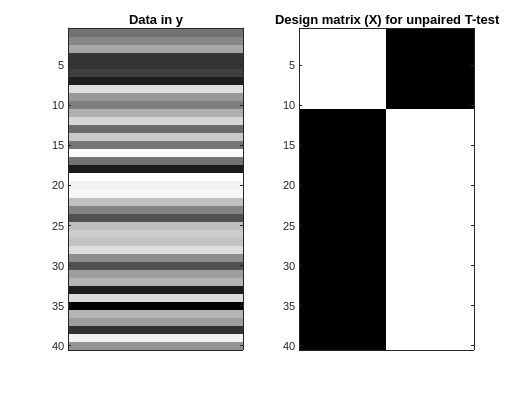

N = [10 30]; yg = {};
yg{1} = sample_pop(pop, N(1), 1);
yg{2} = sample_pop(pop, N(2), 1) + 0.5; % shorthand to add a signal
y = cat(1,yg{:});
X = [[ones(N(1),1); zeros(N(2),1)] [zeros(N(1),1); ones(N(2),1)]];
figure, colormap('gray'), 
subplot(1,2,1), imagesc(y), title('Data in y'), set(gca,'Xtick',[])
subplot(1,2,2), imagesc(X), title('Design matrix (X) for unpaired T-test'), set(gca,'Xtick',[])

The first column of X is a binary, indicator variable that codes which data points come from Group 1, while the second column codes which are from Group 2.

This model can be fit to the data by minimising the squared residuals ("ordinary least squares" estimation). Some simple maths shows that this implies that the parameters can be estimated by multiplying the data by the (pseudo)inverse of the design matrix:

B = pinv(X)*y; % OLS estimate of Betas
fprintf('Parameter (Beta) estimates = %s\n',num2str(B'))

Parameter (Beta) estimates = -0.43742     0.32312


where B are estimates of the true parameters. If you examine pinv(X), you'll see that it is just estimating the mean for each group in this case. We can then reconstruct the model fit, the residuals, and estimate the std of the error, given the df. In the case of independent data, the df is the number of data points minus the number of unique parameters estimated, where the latter is the rank of X (the rank is simply number of columns in X provided the columns are not linearly dependent):

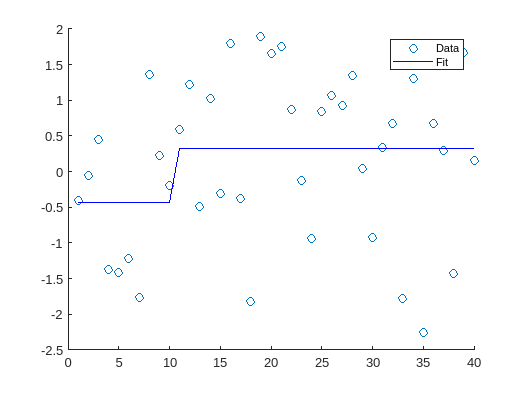

Y = X*B;    % Reconstruct fitted response
r = y - Y;  % Residuals
figure, hold on, plot(y,'o'),plot(Y,'-b'), legend({'Data', 'Fit'})

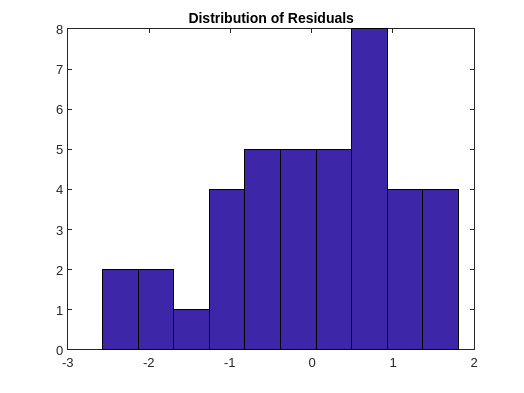

figure, hist(r), title('Distribution of Residuals') % residuals consistent with Gaussian error

df = length(y) - rank(X)

df = 38

sigma = r'*r / df;
fprintf('Estimated std of error = %3.2f\n',sigma)

Estimated std of error = 1.26


The above code is part of "glm_fit" funciton at end.

Having fit the model (and checked the residuals are consistent with assumptions of Gaussian error), we can construct statistics like a T-value, by specifying a "contrast". A contrast is a linear weighting of our parameters, e.g, to test that the mean of Group 2 is bigger than that of Group 1, the contrast would be the row vector c = [-1 1].

c = [-1 1]; % Directional T-contrast testing Group 2 mean bigger than Group 1 mean
T = c*B / sqrt(sigma*c*pinv(X'*X)*c'); % Equation for T-value
p = T2p_higher(T,df); fprintf('P-value from GLM = %4.3f\n',p)

P-value from GLM = 0.036


T2p_higher(two_sample_T(yg,'pooled'),df); fprintf('P-value from above T-test = %4.3f\n',p)

P-value from above T-test = 0.036


You can see the p-values are identical. Although the equation for the T value looks scary, it is generalising ideas above (and note that the GLM always pools the error estimate, and that we have not made any corrections for possible inhomogeniety of variance yet; see later). The above code is part of "glm_con" function at end (while the function "glm" simply calls "glm_fit" followed by "glm_con").

There are few more things useful to know about the GLM. Firstly, we nearly always include a constant term in X, which removes the grand-mean across all datapoints. If we add this to our model, note that the dfs do not change, because this new third column is the sum of the first two (ie linearly dependent). Thus we get the same T-statistic:

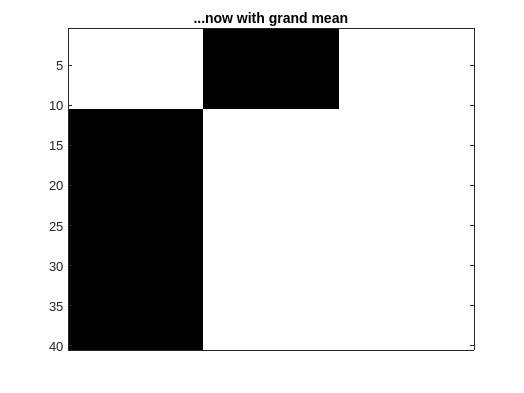

aX = [X ones(sum(N),1)]; 
figure, colormap('gray'), imagesc(aX), title('...now with grand mean'), set(gca,'Xtick',[])

[B, sigma, R2, r] = glm_fit(y, aX);
fprintf('Parameter (Beta) estimates = %s\n',num2str(B'))

Parameter (Beta) estimates = -0.39932     0.36122   -0.038097


fprintf('Proportion of variance explained by model = %3.2f\n',R2)

Proportion of variance explained by model = 0.10


[T, F, df, p] = glm_con(c, aX, B, sigma);
fprintf('P-value from GLM with grand mean = %4.3f\n',p)

P-value from GLM with grand mean = 0.036


R2 - the proportion of variance explained - is a measure of overall model fit (and of effect size if hypothesis specified in terms of X). 

though note the Bs have changed. This is because they now refer to deviations from the grand mean (rather than deviations from zero). Note that one could also specify the model in terms of two colums of X: one for the difference between conditions and one for the average across condition (the constant term). This is essentially a rotation of original X by the transformation T below, so we can simply apply the same transformation to c to test the equivalent contrast: 

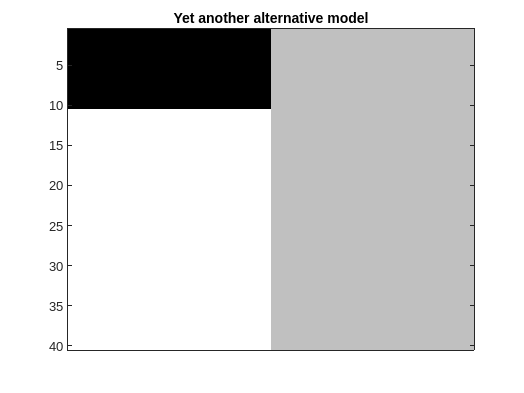

T = [-1 1; 1/2 1/2]';
aX = X*T; figure, colormap('gray'), imagesc(aX), title('Yet another alternative model'), set(gca,'Xtick',[])

ac = c*T;
[B, sigma, R2, r] = glm_fit(y, aX);
[T, F, df, p] = glm_con(ac, aX, B, sigma); fprintf('Contrast now: %s',mat2str(ac'))

Contrast now: [2;0]

fprintf('Parameter estimates = %s',num2str(B'))

Parameter estimates = 0.38027    -0.11429

fprintf('Proportion of variance explained by model = %3.2f\n',R2)

Proportion of variance explained by model = 0.10


fprintf('P-value from rotated GLM = %4.3f\n',p)

P-value from rotated GLM = 0.036


Note that p-value and R2 are unchanged from above (because models span the same space). Note also that the scaling of c does not affect the statistics (though the sign does); nor does scaling X (e.g, doubling the values in X will halve the values of B, but not affect any statistics).

### GLM for paired T-test

We can now illustrate a paired T-test, where we simply add extra columns to X that capture the mean of each participant (note that the glm.m function pads any contrast vector c with 0's for any columns of X not included in the contrast vector provided):

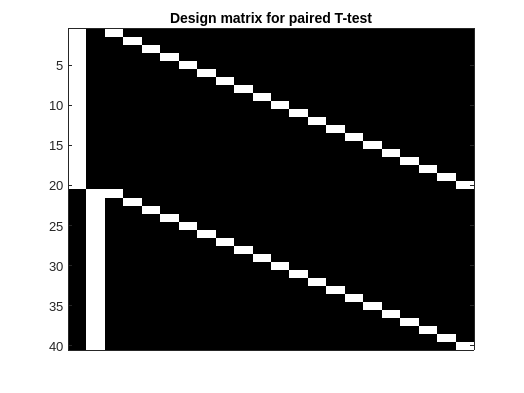

N = 20;
yg{1} = sample_pop(pop, N(1), 1);
yg{2} = yg{1} + randn(N,1)/2 + 0.5; % add signal with correlated effects across participants
y = cat(1,yg{:});

X = [kron(eye(2),ones(N,1)) kron(ones(2,1),eye(N))];
figure,imagesc(X), colormap('gray'), title('Design matrix for paired T-test'), set(gca,'XTick',[])

[B, sigma, R2, r] = glm_fit(y, X);
[T, F, df, p] = glm_con(c, X, B, sigma);
fprintf('Paired GLM: T(%d)=%3.2f, p=%4.3f\n',df(2),T,p)

Paired GLM: T(19)=5.04, p=0.000



[B, sigma, R2, r] = glm_fit(y, X(:,1:2));
[T, F, df, p] = glm_con(c, X(:,1:2), B, sigma);
fprintf('Unpaired GLM: T(%d)=%3.2f, p=%4.3f\n',df(2),T,p)

Unpaired GLM: T(38)=1.31, p=0.099


Note again the smaller p-value for the paired than unpaired model, because its additional columns are capturing additional variance in the data, hence the residuals are smaller, and hence the T-value is higher, which often outweighs the loss in dfs (to the extent that there is between-participant variance in the data, as there is in above case since the data for condition 2 share a contribution from those in condition 1).

*Exercise: convince yourself that the above paired T-test can be reduced to a one-sample T-test within the GLM. Hint apply T = kron([-1 1],eye(N)) (noting that X rank deficient but still works, though could reduce to just its second column, and adjusting contrast to just [1])*

## ANOVA and F-tests

We now turn to experiments with more than two conditions, which are often analysed with "Analysis of Variance" (ANOVA) (thanks again to Fisher). In such cases, we may be interested in any differences between the three or more conditions; a hypothesis that cannot be tested with a T-statistic, but can be tested with the F-statistic. 

Calculation of the F-statistic within the GLM is a bit complex (see glm_con.m at end), but can be throught as comparing the variance explained by two models: the full model (with the effects of interest) relative to a reduced model (without effects of interest), where the effects of interest are specified by an F-contrast. Whereas the contrast vector c for a T-contrast above is always one-dimensional (one row), an F-contrast can have more than one row (i.e., becomes a contrast matrix). This is easiest to explain with the concept of a 1x3 repeated-measures ("within-participant") ANOVA:

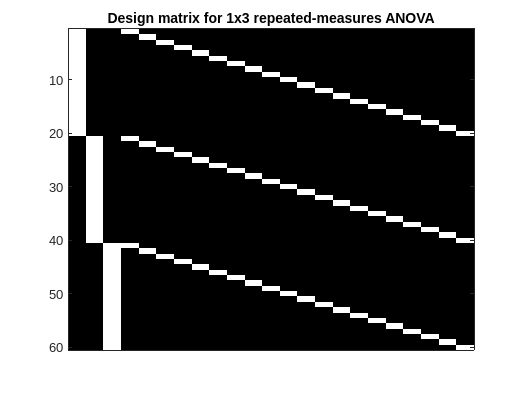

X = [kron(eye(3),ones(N,1)) kron(ones(3,1),eye(N))];
figure,imagesc(X), colormap('gray'), set(gca,'XTick',[])
title('Design matrix for 1x3 repeated-measures ANOVA')

We are now also going to generate data using a multivariate normal distribution (as if we had sampled same person in a population several times), in which we can specify the precise correlation between measures from the same people (the variable "ppt_cor" below, the size of which determines how much more efficient within-participant designs can be, and is a parameter needed for power analyses):

rng(1)
pop_means = kron([1 2 3]/3,ones(N,1)); % Means across 3 conditions
ppt_cor = 0.5; % correlation between measures from same participants
pop_cov = ones(3)*ppt_cor + (1-ppt_cor)*eye(3) % covariance matrix

pop_cov =     1.0000    0.5000    0.5000
    0.5000    1.0000    0.5000
    0.5000    0.5000    1.0000


y = mvnrnd(pop_means,pop_cov); % Generate data
y = y(:); % Concatenate (from "wide" to "long" format)

If we want to test whether the means of the three conditions differ in any way, we can specify an F-contrast like any of those contrast matrices below (which are all equivalent, and have same rank):

fprintf('Equivalent F-contrasts\n')

Equivalent F-contrasts


c = [1 -1 0; 0 1 -1]     % Does condition 1 differ from 2, and 2 from 3?

c =      1    -1     0
     0     1    -1


c = detrend(eye(3),0)    % Does each condition differ from average of other two?

c =     0.6667   -0.3333   -0.3333
   -0.3333    0.6667   -0.3333
   -0.3333   -0.3333    0.6667


c = orth(diff(eye(3))')' % Orthonormal contrast (generally safest)

c =    -0.4082    0.8165   -0.4082
   -0.7071   -0.0000    0.7071


Note also that, whereas T-tests (within GLM) are always directional, F-contrasts are always undirectional, and the sign of the contrast weights does not matter. Indeed, for 1D case, F=T^2, equivalent to a two-tailed T-test. As with a T-contrast, the scaling of the weights within each row does not matter, though that scaling does need to be the same across rows. One way about thinking about an F-contrast is as the union of effects in each row, e.g, for the first contrast above, asking whether conditions 1 and 2 differ AND/OR do conditions 2 and 3 differ. Or in geometric terms, for a 2D design matrix, you can think of a T-test testing (a projection of data onto) one direction through a 2D space, whereas the F-test is testing distance from the origin, i.e, a circular threshold.

The distribution of the F-statistic is determined by two dfs: the numerator df refers to the (dimensionality/rank of) the effects of interest, as specified by the F-contrast (with value 2 here), whereas the denominator df refers to the remaining dfs in the data. A p-value can then be calculated from the parametric distribution of the F-statistic (for which glm_con requires passing the residuals r too):

[B, sigma, R2, r] = glm_fit(y, X);
[T, F, df, p] = glm_con(c, X, B, sigma, r);
fprintf('Main effect in 1x3 ANOVA: F(%d,%d)=%3.2f, p=%4.3f\n',df(1),df(2),F,p)

Main effect in 1x3 ANOVA: F(2,38)=4.53, p=0.017


*Exercise: how can one test for a linear effect across three conditions? You might think a contrast [-1 0 1] on above design matrix will do this, but this only compres the two extreme levels, i.e, could return a significant positive effect even if the means of the data were [1 -3 2], so will also detect nonlinear effects. The solution is to fit a more restricted model with a linear regressor only, by setting X = [X(:,1:3)*[-1 0 1]' X(:,4:end)] and testing a contrast c = [1]. *

## Nonsphericity (inhomogeniety of error (co)variance)

However there are situations in which above p-values can be too small (ie FPR too high). Above we stated that the GLM assumes the error is drawn independently from a single Gaussian. This assumption is sometimes described as the residuals being "white", or "IID", ie, "independent and identically distributed". In fact, the more precise assumption for these ANOVA type designs is that the error covariance across conditions is "spherical". Sphericity is complicated to define, but a common case that meets sphericity is that the covariance matrix has "compound symmetry", which means that all the diagonal values are equal (homogeniety of variance) and all the off-diagonal values are equal (homogeniety of covariance). The pop_cov matrix above is compound symmetric, and the simulations below confirm that the FPR is controlled. But notice what happens between when either homogeniety of variance (as we met above in case of unpaired T-tests) or homogeniety of covariance are not met:

% continuing X and c from above
num_samp = 1e3;
p = nan(num_samp,3);
for s = 1:num_samp
%    pop_cov = eye(3); % IID
    pop_cov = [1 0.5 0.5; 0.5 1 0.5; 0.5 0.5 1]; % 1. compound symmetry
    y = mvnrnd(zeros(N,3),pop_cov); % Null
    y = y(:);
    [B, sigma, R2, r] = glm_fit(y, X);
    [T, F, df, p(s,1)] = glm_con(c, X, B, sigma, r); 
    
    pop_cov = [1 0.8 0.4; 0.8 1 0.8; 0.4 0.8 1]; % 2. inhomogeniety of covariance
    y = mvnrnd(zeros(N,3),pop_cov); % Null
    y = y(:);
    [B, sigma, R2, r] = glm_fit(y, X);
    [T, F, df, p(s,2)] = glm_con(c, X, B, sigma, r);
    
    pop_cov = [0.1 0 0; 0 1 0; 0 0 10]; % 3. inhomogeniety of variance
    y = mvnrnd(zeros(N,3),pop_cov); % Null
    y = y(:);
    [B, sigma, R2, r] = glm_fit(y, X);
    [T, F, df, p(s,3)] = glm_con(c, X, B, sigma, r);
end
fpr = sum(p<alpha)/num_samp;
fprintf('Compound symmetric covariance, FPR=%4.3f\n',fpr(1))

Compound symmetric covariance, FPR=0.051


fprintf('Inhomogeniety of covariance,   FPR=%4.3f\n',fpr(2))

Inhomogeniety of covariance,   FPR=0.070


fprintf('Inhomogeniety of variance,     FPR=%4.3f\n',fpr(3))

Inhomogeniety of variance,     FPR=0.078


Only the first example controls FPR at alpha, while FPR is elevated for the other two cases (the second example of Inhomogeniety of covariance resembles the autocorrelation when y is a timeseries, as discussed later). A common way to correct for this nonsphericity is to adjust (reduce) the dfs, as we saw earlier in Welch's correction for inhomogeneous variances. The general approach uses Satterthwaite approximation but variants include Greenhouse-Geisser or Huyn-Feldt. You can test this by passing a fourth argument to glm.m function below, which tells it how many conditions of interest there are. This estimates the covariance across conditions using the residuals, and reduces the dfs accordingly. 

*Exercise: add the data and number of conditions as additional arguments to glm_con above, eg "glm_con(c, X, B, sigma, r, y, 3)", and you should see the FPR is now kept below alpha in all cases. *

However, this method is conservative (particularly when there are only a few observations relative to number of unique elements in the covariance matrix). Furthermore, the estimate of the population covariance from the residuals is inaccurate because it includes covariance induced by first fitting the model. The proper way to estimate the population error covariance is to estimate (a model of) the error simultaneously with fitting the design matrix. This requires an iterative algortihm like Restricted Maximum Likelihood (ReML). ReML is related to heirarchical linear and mixed effects models covered later.

For this ANOVA case, the error is modelled by a number of "variance" components (these are the "Qs" in glm_con function): for the 1x3 example, there would be 3 components to model the 3 variances, and another 3 to model the 3 covariance terms. The weightings of these are called hyperparameters. Later, we will use an AR(1) model to capture temporal autocorrelation when a GLM is fit to timeseries data.

*Exercise (advanced): You can try ReML by adding the final argument of "1" to glm_con in lines above, though note it will take a long time. You could then examine the hyperparameters, h, and use them to build the weighted sum of the corresponding covariance components, Q, to check that pop_cov has been estimated well. Note that estimation will be more accurate when there are more datapoints (and in imaging, we often pool the data across voxels/samples to get a more accurate estimate of the error covariance).*

### Factorial designs and pooled vs partitioned error

Often experimental conditions are generated by a factorial design, where each condition corresponds to one level of each of multiple factors. For example, a design with two factors each with two levels would have 4 conditions, and corresponds to "2x2 ANOVA". Factorial designs are associated with a common set of hypotheses: main effects of each factor plus interactions between them. For example, if we have factor F1 with levels A and B, and factor F2 with levels 1 and 2, and we order the four conditions in X as [A1 A2 B1 B2], then 

c1 = kron([-1 1], [1  1]) % Main effect of F1

c1 =     -1    -1     1     1


c2 = kron([1  1], [-1 1]) % Main effect of F2

c2 =     -1     1    -1     1


c3 = kron([-1 1], [-1 1]) % Interaction between F1 and F2 (difference of differences)

c3 =      1    -1    -1     1


More generally, all possible main effects and interactions in a factorial design can be generated by the Kronecker product of two contrasts for each factor: "ones(N(f))" and the orthonormal contrast defined in the F-contrasts section above, where N(f) = number of levels for factor f, eg: 

N = [2 3]; % 2 x 3 ANOVA
m = {}; d = {};
for f = 1:length(N)
    m{f} = ones(1,N(f));
    d{f} = orth(diff(eye(N(f)))')';
end
c = kron(m{1},d{2}) % Example of main effect of second factor in 2x3 design

c =    -0.4082    0.8165   -0.4082   -0.4082    0.8165   -0.4082
   -0.7071   -0.0000    0.7071   -0.7071   -0.0000    0.7071


c = kron(d{1},d{2}) % Example of interaction between two factors in 2x3 design

c =     0.2887   -0.5774    0.2887   -0.2887    0.5774   -0.2887
    0.5000    0.0000   -0.5000   -0.5000   -0.0000    0.5000


*Interesting factoid: Leonold Kronecker's famous saying was "Die ganzen Zahlen hat der liebe Gott gemacht, alles andere ist Menschenwerk" ("God made the integers, all else is the work of man")*

When all conditions are between-participant (i.e., each condition is a group), we can have a single X with as many columns as there are groups, within which we can evaluate every contrast like above (possibly modelling inhomongeniety of variance). When one more more factors are within-participant, however, we have an additional option to "partition" the error term (rather than the pooled error used so far). Because the columns in X for ANOVA designs are orthogonal, we can use a separate error term for each ANOVA effect (equivalent to the effect-by-participant interaction). This is equivalent to fitting a smaller GLM to each effect separately. So for a 2x2 design in which both factors are within-participant, we can fit:

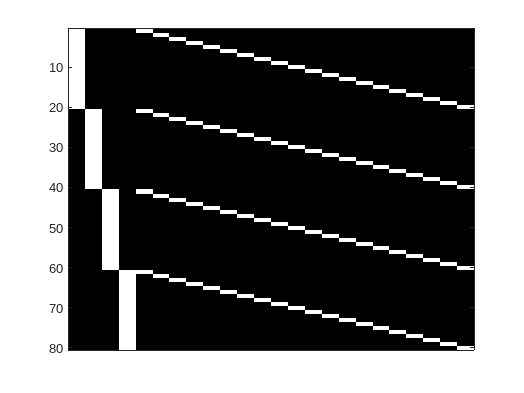

rng(3)
N = 20;
X = [kron(eye(4),ones(N,1)) kron(ones(4,1),eye(N))];
figure,imagesc(X),colormap('gray'), set(gca,'XTick',[])

es = [3 2 1]/3; % Effect sizes for main effects and interaction (not standardised effect sizes though!)
es = es * [c1; c2; c3]/4; % using ANOVA contrasts above 
pop_means = kron(es,ones(N,1));
pop_cov = ones(4)*ppt_cor + (1-ppt_cor)*eye(4); % error covariance matrix
%pop_cov = [1 0.8 0 0; 0.8 1 0 0; 0 0 0.5 0.3; 0 0 0.3 0.5]; % nonspherical case
y = mvnrnd(pop_means,pop_cov); % Generate data
y = y(:);
% Pooled error (using c1-c3 effect contrasts from above)
[B, sigma, R2, r] = glm_fit(y, X);
[T, F, df, p] = glm_con(c1, X, B, sigma);
fprintf('Contrast %s, F(%d,%d) = %3.2f, pooled p=%4.3f\n',mat2str(c1),df(1),df(2),F,p)

Contrast [-1 -1 1 1], F(1,57) = 5.49, pooled p=0.011


[T, F, df, p] = glm_con(c2, X, B, sigma);
fprintf('Contrast %s, F(%d,%d) = %3.2f, pooled p=%4.3f\n',mat2str(c2),df(1),df(2),F,p)

Contrast [-1 1 -1 1], F(1,57) = 4.37, pooled p=0.020


[T, F, df, p] = glm_con(c3, X, B, sigma);
fprintf('Contrast %s, F(%d,%d) = %3.2f, pooled p=%4.3f\n',mat2str(c3),df(1),df(2),F,p)

Contrast [1 -1 -1 1], F(1,57) = 0.02, pooled p=0.557


% Partitioned error (using c1-c3 effect contrasts from above)
c = kron(c1,eye(N)); [B, sigma, R2] = glm_fit(c*y, ones(N,1)); % c*X reduces to ones(N,1) is this example
[T, F, df, p] = glm_con(1, ones(N,1), B, sigma, r); 
fprintf('Contrast %s, F(%d,%d) = %3.2f, partitioned p=%4.3f\n',mat2str(c1),df(1),df(2),F,p)

Contrast [-1 -1 1 1], F(1,19) = 11.91, partitioned p=0.001


c = kron(c2,eye(N)); [B, sigma, R2] = glm_fit(c*y, ones(N,1)); % c*X reduces to ones(N,1) is this example
[T, F, df, p] = glm_con(1, ones(N,1), B, sigma, r); 
fprintf('Contrast %s, F(%d,%d) = %3.2f, partitioned p=%4.3f\n',mat2str(c2),df(1),df(2),F,p)

Contrast [-1 1 -1 1], F(1,19) = 2.84, partitioned p=0.054


c = kron(c3,eye(N)); [B, sigma, R2] = glm_fit(c*y, ones(N,1)); % c*X reduces to ones(N,1) is this example
[T, F, df, p] = glm_con(1, ones(N,1), B, sigma, r); 
fprintf('Contrast %s, F(%d,%d) = %3.2f, partitioned p=%4.3f\n',mat2str(c3),df(1),df(2),F,p)

Contrast [1 -1 -1 1], F(1,19) = 0.02, partitioned p=0.556


(Note here that c*X has many columns, but all linearly dependent with a column of ones, so c*X is equivalent to ones(N,1), i.e, a one-sample test.) The p-values from the pooled error are often (but not always) smaller, due to larger dfs, but those from the partitioned approach are safer because the error covariance matrix is smaller (since fewer conditions per model), so sphericity assumptions more likely to be met (indeed, when only 2 levels per factor, as here, the GLM only has one column and hence one covariance term, so must be spherical by definition). 

*Exercise: if you want to check robustness of partitioned error to nonspheriricty, try the extreme case of nonsphericity commented out for pop_cov above, but run over num_samp studies to calculate FPR*

Note permutation testing is possible with these more complex ANOVA models, but the exchaneability requirement restricts how exactly participants can be swapped between conditions (and for the case of timeseries considered below, one can phase-shuffle data while maintaing power spectrum, i.e, autocorrelation). In general, the power of the parametric assumptions of the GLM comes with the flexibility they afford, as exemplified below.

## Continuous regressors (multiple regression)

So far we have applied the GLM to experiments with one or more conditions, in which the values in X are binary, but it can equally be applied to continuous values in X, e.g, to perfom multiple regression. The simplest example of this is to estimate the correlation between two variables:

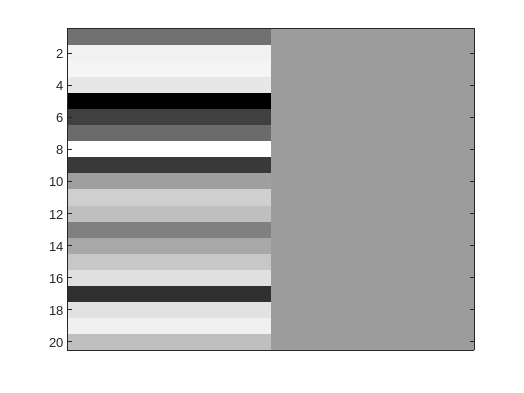

rng(1)
pop_cov = ones(2)*ppt_cor + (1-ppt_cor)*eye(2);
y = mvnrnd(ones(N,2),pop_cov); % mean of 1
[R,Rp] = corr(y(:,1),y(:,2));  % Pearson correlation
X = [y(:,2) ones(N,1)]; figure, imagesc(X), colormap('gray'), set(gca,'XTick',[])

[T,F,df,p,B] = glm(y(:,1), X, [1 0]); 
fprintf('Pearson correlation, R(%d)=%3.2f, p=%4.3f\n',N,R,Rp)

Pearson correlation, R(20)=0.39, p=0.087


fprintf('GLM F-test, F(%d,%d)=%3.2f, p=%4.3f\n',df(1),df(2),F,2*p) % two-tailed p

GLM F-test, F(1,18)=3.27, p=0.087


The F-contrast on first column of X gives same p-value as standard Pearson correlation. Note that it is important to include the second, constant term in X, to remove the mean (if you do not include it, and the means of y(:,1) and y(:,2) are not zero, then the p-value will not correspond to a correlation, but include the effect of the means). You will also note that the sqrt(R2) does not equal the Pearson correlation coefficient r. This is because R2 above refers to whole model fit, including mean. To estimate the Pearson correlation coefficient, you could mean-correct y (though there are other ways of calculating R2 from sub-spaces of X specified by the contrast):

my = y - repmat(mean(y),N,1); % mean-correct y
[T,F,df,p,~,R2,r] = glm(my(:,1), my(:,2), 1);
fprintf('GLM R=%3.2f, F(%d,%d)=%3.2f, p=%4.3f\n',sqrt(R2),df(1),df(2),T,p*2) % two-tailed p

GLM R=0.39, F(1,19)=1.86, p=0.079


While we have now recovered the Pearson coefficient, note that the p-value is not correct, because we removed df's from the data when we mean-corrected, but not told the model about this. This is why it is generally best not to perform any operations on the data (like mean-correction) before entering the GLM, but build these into the GLM instead (e.g, adding a constant term, or filter the model if also filtering the timeseries, see later).

*Interesting factoid: Karl Pearson made many contributions of statistics to empirical sciences, though like his colleague Fisher, he was tarred by his views on eugenics. However, correlation is not causation, and statistical training does not necessarily result in eugenic beliefs.*

We can plot the fit and data from the original example above:

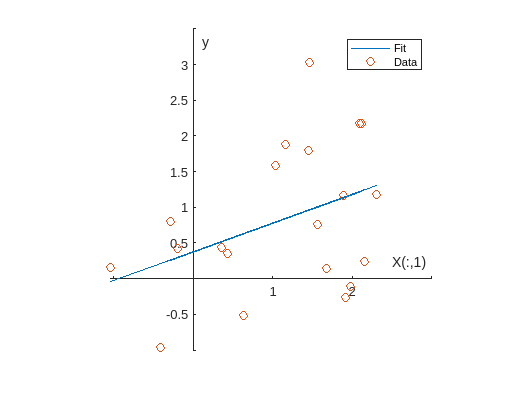

Y = X*B; % reconstruct fitted response, where B(1) is slope and B(2) is intercept
figure,hold on,plot(X(:,1),Y,'-'),plot(y(:,2),y(:,1),'o'); legend({'Fit','Data'}), axis square
set(gca, 'XAxisLocation', 'origin', 'YAxisLocation', 'origin'), ylabel('y'), xlabel('X(:,1)')

fprintf('Parameter estimates from original GLM above: B1=%3.2f, B2=%3.2f',B(1),B(2))

Parameter estimates from original GLM above: B1=0.40, B2=0.37

You can see that B1 corresponds to the slope of the fit (regression line), whereas B2 is the intercept (value expected when variable in X(:,1) is zero). What happens if we mean-correct X(:,1): 

mX = X;
mX(:,1) = X(:,1) - mean(X(:,1));
[T,F,df,p,mB] = glm(y(:,1), mX, [1 0]);
fprintf('GLM F-test, F(%d,%d)=%3.2f, p=%4.3f\n',df(1),df(2),F,p*2)

GLM F-test, F(1,18)=3.27, p=0.087


fprintf('Parameter estimates after mean-correction: B1=%3.2f, B2=%3.2f',mB(1),mB(2))

Parameter estimates after mean-correction: B1=0.40, B2=0.82

fprintf('Mean of data=%3.2f',mean(y(:,1)))

Mean of data=0.82

You can see that B1 (the slope) has not changed (and nor have the statistics), but B2 has, and it now reflects the mean of the data, not the intercept. This is a special case of orthogonalising regressors, to which we now turn.

### Correlated Regressors and Orthogonalisation

Let's now fit the data will two continuous regressors, but make them highly correlated:  

rng(1)
pop_cov = [1 0.5 0.5; 0.5 1 0.9; 0.5 0.9 1]

pop_cov =     1.0000    0.5000    0.5000
    0.5000    1.0000    0.9000
    0.5000    0.9000    1.0000


y = mvnrnd(ones(N,3),pop_cov); % mean irrelevant for below

If we fit each regressor separately, the p-value is usually small:

[T,F,df,p] = glm(y(:,1), y(:,2), 1); fprintf('Separate GLM T-test for 1st regressor, p=%4.3f\n',p)

Separate GLM T-test for 1st regressor, p=0.000


[T,F,df,p] = glm(y(:,1), y(:,3), 1); fprintf('Separate GLM T-test for 2nd regressor, p=%4.3f\n',p)

Separate GLM T-test for 2nd regressor, p=0.000


However, when we add both to the same model:

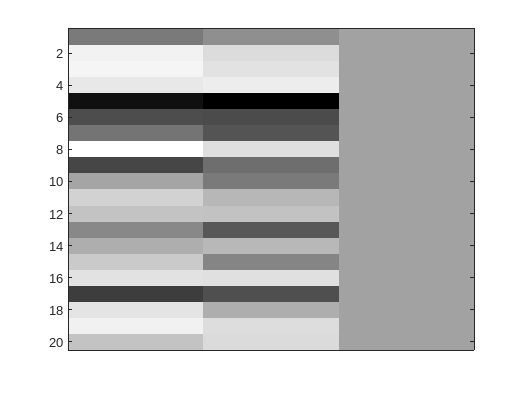

X = [y(:,2:3) ones(N,1)]; figure, imagesc(X), colormap('gray'), set(gca,'XTick',[])

[B, sigma, R2, r] = glm_fit(y(:,1), X);
[T, F, df, p] = glm_con([1 0 0], X, B, sigma); fprintf('Joint GLM T-test for 1st regressor, p=%4.3f\n',p)

Joint GLM T-test for 1st regressor, p=0.750


[T, F, df, p] = glm_con([0 1 0], X, B, sigma); fprintf('Joint GLM T-test for 2nd regressor, p=%4.3f\n',p)

Joint GLM T-test for 2nd regressor, p=0.067


rarely is either individual regressor significant. This is because they GLM only tests the unique variance explained by each regressor. Sometimes people orthogonalise one regressor with respect to the other. This can be done with the "orthog" function below (which actually just residualises one regressor by fitting a GLM that predicts it by the other). So let's orthogonalise the first regressor with respect to the second:

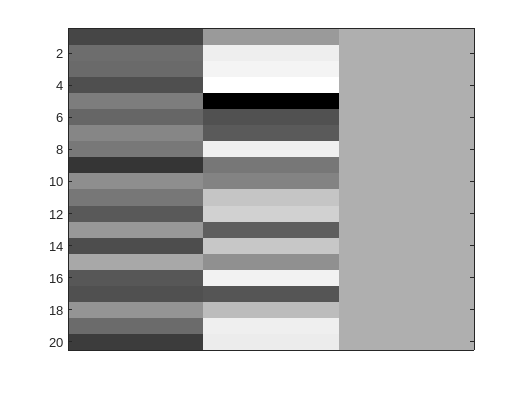

orthog = @(x,y) x - y*(pinv(y)*x); % orthogonalise x with respect to y
oX = X; oX(:,1) = orthog(X(:,1),X(:,2));
figure, imagesc(oX), colormap('gray'), set(gca,'XTick',[]) 

fprintf('Previous Betas:                %s\n',num2str(B'))

Previous Betas:                -0.37058     0.89508     0.40957


[B, sigma, R2, r] = glm_fit(y(:,1), oX);
fprintf('Betas after orthogonalisation: %s\n',num2str(B'))

Betas after orthogonalisation: -0.37058      0.4911     0.40957


[T, F, df, p] = glm_con([1 0 0], oX, B, sigma); fprintf('Orthog GLM T-test for 1st regressor, p=%4.3f\n',p)

Orthog GLM T-test for 1st regressor, p=0.750


[T, F, df, p] = glm_con([0 1 0], oX, B, sigma); fprintf('Orthog GLM T-test for 2nd regressor, p=%4.3f\n',p)

Orthog GLM T-test for 2nd regressor, p=0.026


As with mean-correction above, the Beta for the regressor that has been orthogonalised (B1) does not change, but that for the other (B2) does, because now the common variance between the two has been assigned to it. However, there is no magic here - one cannot know in general to which of two correlated variables to assign the common variance - so there should always be an independent reason for giving priority to one variable over another. (Sometimes, in unbalanced ANOVA designs in which the columns of X are no longer orthogonal, priority is given to lower-order effects, e.g. main effects over interactions. This corresponds to differences between "Type I, II and III sum of squares"; which are effectively just different orders of orthogonalisation.)

Note that sometimes the GLM regressors are Z-scored; again, this does not affect tests of the reliability of individal parameter estimates, but the scaling by their std will affect contrasts between regressors (and is often important to put the parameters onto the same scale, ie make them commensurate, if they do not have meaningful units of comparison).

### Efficiency

Importantly, high correlation between regressors in a GLM reduces the power with which their contributions (parmeters) can be estimated. It does not bias the parameter estimates or statistical tests on them (as is sometimes thought); it just makes the estimates highly variable across experiments (ie different data samples). Indeed, the correlation between regressors is inherent to the definition of the efficiency of a GLM to test a specific hypothesis, which is a function of the design matrix and contrast:

efficiency = @(X,c) trace(c*inv(X'*X)*c')^-1; % scaling arbitrary

High correlation between columns of X reduces the middle term in this equation. Note however that the contrast itself also matters, so it may not matter if regressors are (negatively) correlated, but one only cares about the difference between them, as example below, where efficiency for the difference between the slopes of two regressors is much higher than that for their average slope: 

rng(1)
X = [mvnrnd(ones(N,2),[1 -0.5; -0.5 1]) ones(N,1)];
c = [1 1 0]; fprintf('Efficiency of contrast %s: %3.2f\n',mat2str(c),efficiency(X,c))

Efficiency of contrast [1 1 0]: 4.73


c = [1 -1 0]; fprintf('Efficiency of contrast %s: %3.2f\n',mat2str(c),efficiency(X,c))

Efficiency of contrast [1 -1 0]: 17.12


Or in the extreme case, the columns of a two-sample T-test are perfectly anti-correlated, which means one cannot estimate one condition independently of the other (when a constant term is included), and efficiency above is not defined, but one can still estimate the difference between them.

*Exercise (advanced): this definition of efficiency is helpful when comparing different fMRI designs, where the effects of correlations between regressors induced by the HRF and the onsets of different conditions is difficult to intuit. You could try estimating efficiency for variants of the fMRI GLM below (taking care the scaling of X and c are important to match).*

### Nonlinear effects

Finally, we are assuming a linear relationship between y and X(:,1). In general it could be nonlinear, and while there are several ways of modelling this, the simplest approach is through a polynomial expansion, here to second-order (using "polynom" function at end):

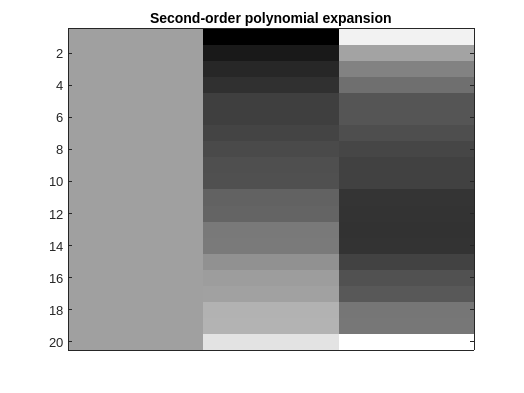

X = sort(X(:,1)); % expand first regressor from above; sorted to aid visualisation
y = detrend(detrend(X,0).^2,0) + randn(N,1); % Create quadratic effect plus noise
X = polynom(X,2);
figure,imagesc(X),colormap('gray'), set(gca,'XTick',[]), title('Second-order polynomial expansion')

[T,F,df,p] = glm(y, X, [1 0 0]); fprintf('0th-order (intercept) effect, p=%4.3f\n',p)

0th-order (intercept) effect, p=0.974


[T,F,df,p] = glm(y, X, [0 1 0]); fprintf('1st-order (linear) effect, p=%4.3f\n',p)

1st-order (linear) effect, p=0.056


[T,F,df,p] = glm(y, X, [0 0 1]); fprintf('2nd-order (quadratic) effect, p=%4.3f\n',p)

2nd-order (quadratic) effect, p=0.000


(Here there is a good reson to orthogonalise higher order terms with respect to lower order ones). 

More generally, there are generalisations of the GLM that insert a nonlinear "linkage" function between y and X (i.e, a logistic function when the data are proportions, i.e. bounded between 0 and 1). These are often available in statistical packages but beyond the present remit.

## Timeseries data

In imaging, the data are often timeseries that are autocorrelated (e.g, fMRI data from a voxel, or ERP timepoints). Some of this autocorrelation comes from the signal we wish to model. So in fMRI for example, neural activity is expressed via a hemodynamic response function (HRF) that may last ~30s, which we may sample every 1s. Assuming an HRF given by the "canonical_hrf" function at end, we can simulate fMRI data by convolving it with delta functions that represent brief neural activity assumed to occur whenever we present a stimulus:

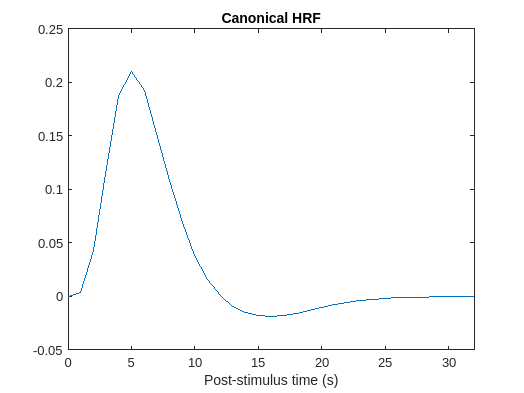

hrf = canonical_hrf(1); figure, plot([0:32],hrf);
axis([0 32 -0.05 0.25]),xlabel('Post-stimulus time (s)');  title('Canonical HRF')

N = 270; % A run of 270 fMRI scans
% Create some onsets, roughly jittered across run:
%r = randperm(N); r = r(1:20);
r = [1 12 35 40 50 80 82 100 132 157 168 180 210 220 235 245]; % reasonably-spaced (random selection too random!)
ons = zeros(N,1); ons(r) = 1;
figure,plot(ons),hold on, title('Stimulus onsets, predicted fMRI response and data')
% Convolve with HRF
y = conv(ons, hrf); y=y(1:N); y = y/std(y); % scale so visible on same axis
plot(y)

Some of the autocorrelation comes from the noise though - for example, neural activity unrelated to our stimuli, which would also be expressed via the HRF, plus slow "scanner drift" (and aliased biorhythms):

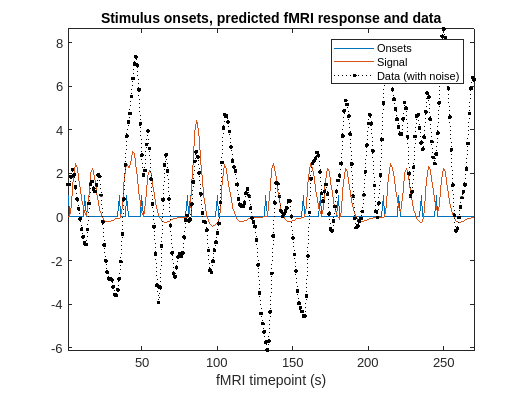

rng(2); % ensure some reasonable (reproducible) noise
n = conv(randn(N,1)*5, hrf); n=n(1:N); % non-stimulus-locked neural noise, expressed through same HRF
y = y + n;
n = sum(polynom([1:N]',2),2); % Slow (polynomial) drift
y = y + n;
plot(y,':k.'), axis tight; xlabel('fMRI timepoint (s)');
legend({'Onsets','Signal','Data (with noise)'})

### Temporal Basis Sets, Filtering and Autocorrelated error

If we do not know the shape of the HRF, we can use a "temporal basis set". Several options are discussed in the literature, but here will use an "FIR" basis set of tophat functions every 2s of the 30s after each onset. This produces the design matrx below, which we can fit with a GLM and estimate:

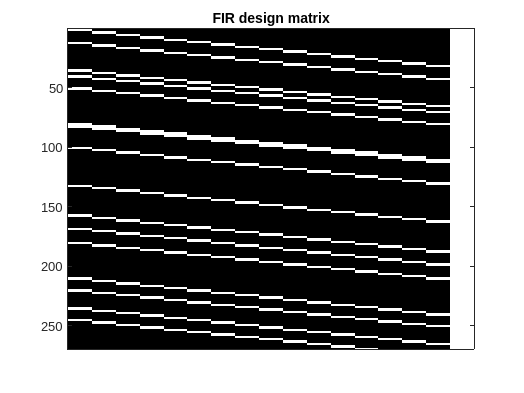

FIR = kron(eye(16),[1 1]');
X = [];
for b = 1:size(FIR,2)
    X(:,b) = conv(ons, FIR(:,b));
end
X = [X(1:N,:) ones(N,1)];
figure,imagesc(X),colormap('gray'), set(gca,'Xtick',[]), title('FIR design matrix')

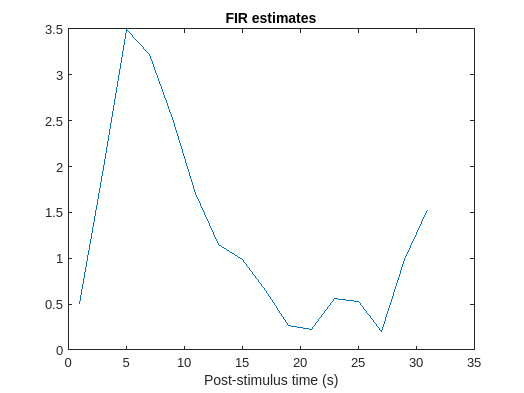

[B, sigma, R2, r] = glm_fit(y, X);
figure,plot([1:2:32],B(1:16)),xlabel('Post-stimulus time (s)'); title('FIR estimates')

[T, F, df, p] = glm_con(eye(16), X, B, sigma, r);
fprintf('F-test for FIR (assuming error white), F(%d,%d)=%3.2f, p=%4.3f\n',df(1),df(2),F,p)

F-test for FIR (assuming error white), F(16,253)=5.62, p=0.000


Note that the FIR parameters roughly resemble the true HRF used to create the data, and the F-test suggests that there is a (highly) significant stimulus-locked response (which in principle could be of any shape). However, this F-test assumes the error is IID, ie spherical, which we can see is unlikely from the residuals, which show some temporal smoothness and slow drift, given the way the noise was created above:

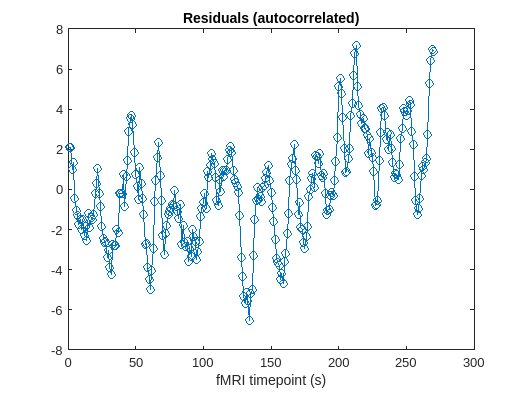

figure, plot(r,'o-'); xlabel('fMRI timepoint (s)'); title('Residuals (autocorrelated)')

Some of the typical autocorrelation in fMRI noise (that induced by the slow drift above) can be removed by high-pass filtering, which can be achieved by adding a set of sinusoids to the design matrix:

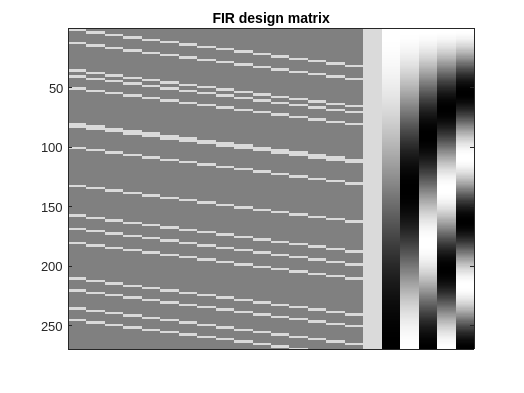

HPC = fix(2*N/128 + 1); % DCT cutoff if highpass filtering to 1/128s
DCT = nan(N,HPC); t = [0:(N-1)];
for k=1:HPC
    DCT(:,k) = sqrt(2/N)*cos(pi*(2*t+1)*k/(2*N));
end
X = [X zscore(DCT)]; % Zscore just to visualise 
figure,imagesc(X),colormap('gray'), set(gca,'Xtick',[]), title('FIR design matrix')

[B, sigma, R2, r] = glm_fit(y, X);
[T, F, df, p] = glm_con(eye(16), X, B, sigma, r);
fprintf('F-test for FIR (after filtering), F(%d,%d)=%3.2f, p=%4.3f\n',df(1),df(2),F,p)

F-test for FIR (after filtering), F(16,248)=8.05, p=0.000


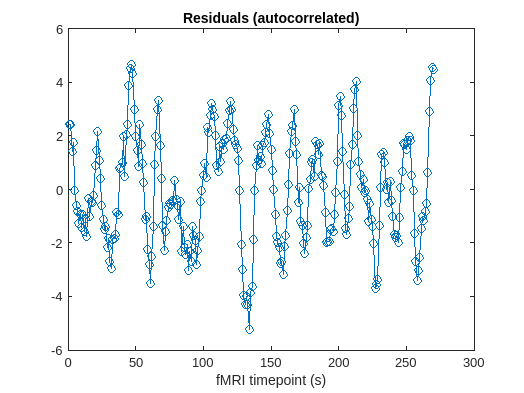

figure, plot(r,'o-'); xlabel('fMRI timepoint (s)'); title('Residuals (autocorrelated)')

While the residuals no longer show slow drift (and the F-statistic has increased), they are still autocorrelated, which is where methods like ReML are effective at modelling this autocorrelation. To model this specific type of nonsphericity, an AR(p) model (p-th order autoregressive model) is often used. Here we assume an AR(1) model, which produces a covariance component like below:

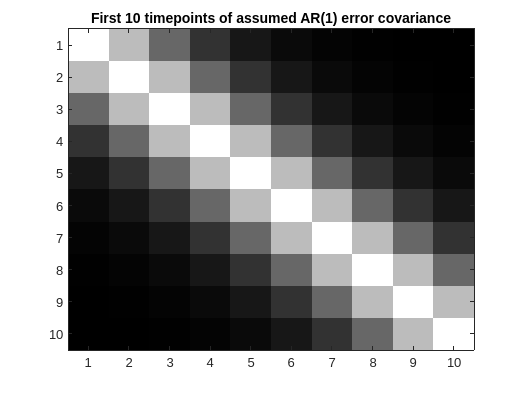

[T, F, df, p, Q] = glm_con(eye(16), X, B, sigma, r, y, 0, 2);
figure,imagesc(Q{2}(1:10,1:10)),colormap('gray'), 
title('First 10 timepoints of assumed AR(1) error covariance')

fprintf('F-test for FIR (assuming AR(1)), F(%3.2f,%3.2f)=%3.2f, p=%4.3f\n',df(1),df(2),F,p)

F-test for FIR (assuming AR(1)), F(10.43,85.97)=4.28, p=0.000


Note also that estimated the error covariance is very noisy (e.g, if you plot the outer-product of the residuals from above, i.e. r*'r, you cannot see the AR(1) pattern clearly). One way to improve its estimation is to pool data across samples, e.g, voxels. If we assume the error covariance is identical across voxels (bar a scaling constant), we can estimate it much more precisely by repeating the above for many voxels, as shown below. Note that we are can call the "glm_fit" function with a matrix rather than vector of data.

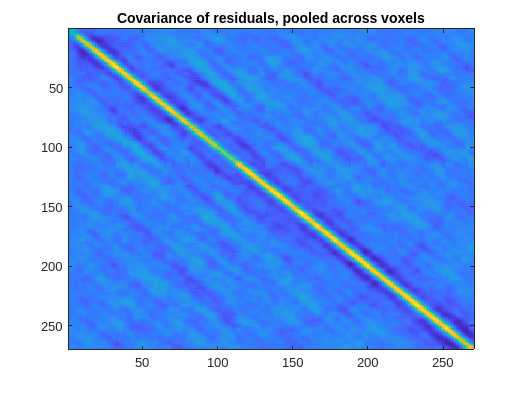

y = conv(ons, hrf); y = y(1:N);
num_samp = 1e3;           % Number of voxels (samples)
y = repmat(y,1,num_samp); % Duplicate signal across voxels
n = nan(N,num_samp);
for v=1:num_samp          % Independent noise but with similar autocorrelation
    tmp = conv(randn(N,1)/2, hrf); 
    n(:,v) = tmp(1:N); 
end
y = y + n;
[B, sigma, R2, r] = glm_fit(y, X);
%figure,plot(mean(B,2)) % (much nicer HRF estimates!)
figure,imagesc(r*r'), title('Covariance of residuals, pooled across voxels') % smoothness now visible

Having estimated the nonsphericity in the error, rather than adjusting the df's, both sides of the GLM can be pre-multiplied by the inverse of this error covariance estimate. This is called "pre-whitening", because now the original dfs are recovered, and the parameters are estimated more efficiently, but this is beyond the scope of the present demonstrations. 

## Heirarchical Linear Models

So far, we have modelled just one source of variance, e.g, across participants in the T-tests and ANOVAs, or across timepoints in the timeseries analyses. We often have mulitple measurements (within each condition) for each of mulitple participants. For example, we might collect reaction times from 100 trials in each of 10 participants. In this case, our power depends on both the variance across trials within participants, and the variance in the mean across participants. This can be modelled properly in "mixed effects" models below, but first we start with a common approximation, which is to average across trials within each participant, and simply perform a test on these means across participants (i..e, ignoring the error associated with each trial-average). 

This is sometimes called the "summary statistic" or two-stage approach. It is illustrated below, along with effects of the number of trials relative to number of participants:

num_ppt = [10  20 10]   % Number of participants

num_ppt =     10    20    10


num_trl = [100 10 20]   % Number of trials per participant

num_trl =    100    10    20


pop_std = [1  1  1]     % Std of mean across participants

pop_std =      1     1     1


trl_std = [10 10 10]    % Std across trials

trl_std =     10    10    10


pop_mean = 1;
num_samp = 1e3;
for e = 1:size(num_ppt,2)
    pop_ppt  = pop*pop_std(e) + pop_mean;
    ppt_mean = sample_pop(pop_ppt,num_ppt(e),num_samp);
    y = nan(num_ppt(e),num_samp);
    for p = 1:num_ppt(e)
        for s = 1:num_samp
            pop_trl  = pop*trl_std(e) + ppt_mean(p,s);
            ppt_vals = sample_pop(pop_trl,num_trl(e),1);
            y(p,s)   = mean(ppt_vals);
        end
    end
    pval = T2p_higher(onet(y),num_ppt(e)-1);
    pr   = sum(pval<alpha)/num_samp;
    fprintf('Positive rate with %d participants with %d trials = %3.2f\n',num_ppt(e),num_trl(e),pr)
end

Positive rate with 10 participants with 100 trials = 0.67
Positive rate with 20 participants with 10 trials = 0.36
Positive rate with 10 participants with 20 trials = 0.31


In this situation where variability across trials is much higher than variability across participants, having 10x more trials produces higher power than having 2x more participants, though if num_ppt*num_trls is fixed, generally better to have more participants in this situation. 

*Exercise: Try situation where variability across trials is less than than variability across participants?*

But what happens if different participants have different numbers of trials? In this case, the mean for participants with more trials is a more accurate estimate, so we could increase the contribution of this participant's mean to the estimate of the population mean. This is called "weighting" (a simple case of "weighted least squares"), which can produce more sensitive tests, as illustrated below:

% pop_mean, num_samp etc as above
rng(1)
num_ppt = 20

num_ppt = 20

pop_std = 1

pop_std = 1

trl_std = 10 

trl_std = 10

% participants ordered by number of trials!
num_trl = []; for p = 1:num_ppt; num_trl(p) = 10*p; end

pop_ppt  = pop*pop_std + pop_mean;
ppt_mean = sample_pop(pop_ppt,num_ppt,num_samp);

samp_means = nan(num_ppt,num_samp);
samp_vals  = nan(sum(num_trl),num_samp); 
for s = 1:num_samp
    vals = [];
    for p = 1:num_ppt
        pop_trl  = pop*trl_std + ppt_mean(p,s);
        ppt_vals = sample_pop(pop_trl,num_trl(p),1);
        samp_means(p,s) = mean(ppt_vals);
        vals = [vals; ppt_vals];
    end
    samp_vals(:,s) = vals; % Used in LME below
end

% unweighted test on means
pval = T2p_higher(onet(samp_means),num_ppt-1);
fprintf('Power for standard T-test = %3.2f\n',sum(pval<alpha)/num_samp)

Power for standard T-test = 0.83



% weighted least squares
w = repmat(num_trl',1,num_samp);
wm = sum(samp_means.*w) ./ sum(w);
wv = (sum(w.*(samp_means.^2))./mean(w) - num_ppt*wm.^2) /(num_ppt-1);
T = wm./(sqrt(wv)/sqrt(num_ppt));
pval = T2p_higher(T,num_ppt-1);
fprintf('Power for weighted T-test = %3.2f\n',sum(pval<alpha)/num_samp)

Power for weighted T-test = 0.92


Note how giving more weight to participants whose mean has been estimated from more trials results in a more powerful final test. Such highly "unbalanced" designs, in which summary statistics are estimated with quite different efficiency across participants, are where the two-stage apporach (that ignores estimation errror associated with each participant) becomes non-optimal. However, this weighting is just a simple case of more general "mixed effects" models, to which we next turn, in which one can have more than one random effect, i.e., variance due to participants, variance due to trials, etc...

More generally, this situation can be explained as a heirarchical set of GLMs:

    y    = X1 * B1 + e1

    B1  = X2 * B2 + e2

So in example above, B1 is the mean across trials for each participant, while B2 is the mean across participants (since here X1 and X2 are just constant terms). In a Bayesian context, B2 can also function as an "empirical prior" that can "regularise" the estimates of individual participant means (B1). Note that there can be more than 2 levels (e.g, trials, sessions, participants), and also that the second level does not have to refer to participants; the second-level could refer to the mean across voxels for example.

## Linear Mixed Effects (LME) Models

We finish with LME models, which can no longer be solved by simply matrix inversion, and require iterative techniques like ReML above. Because these are quite complex in general, we switch to Matlab's built-in LME functions. First, we need to represent the data more generally, in which each observation is a row, and each column indicates where that observation comes from, e.g, a particular participant ID, condition and possiby a particular stimulus ID (sometimes called "long-format"). In Matlab, these are called "tables". 

Let's start by creating a long-format table for the data created above, with just one condition and variable numbers of trials across participants:

part_ID = [];
for p = 1:num_ppt
    part_ID = [part_ID; p*ones(num_trl(p),1)]; 
end
% Just take first random sample
tab = table(samp_vals(:,1),part_ID,'VariableNames',{'y','Participant'});
tab([1:3 11:13],:)

ans = 6×2 table
       y        Participant
    ________    ___________

       6.101         1     
     -8.6235         1     
    -0.37935         1     
      3.3417         2     
     0.73825         2     
     -3.2048         2     


We can now fit an LME model. The generic notation for such a model is "y ~ 1 + F1 + (1 + F1|R1)", where the "1" represents the intercept, F1 is a fixed effect and R1 is a random effect (e.g., participants). We will demonstrate more than one fixed and random effect later. The term "(1|R1)" is known as the "random intercept" (e.g, capturing the mean of each participant; akin to the participant columns in the GLM section earlier), and the term "(F1|R1)" is a "random slope" (e.g, allowing for the possibility that different participants show different size of effects of F1, akin to the error partition corresponding to effect-by-participant interactions in the above GLM section).

However, for the one-sample T-test example above, there is just an intercept (no other fixed effect) and there is only a random intercept, so the model is simply "y ~ 1 + (1|participant)". Using the values in all_vals from preceding section we can see the power of LME:

pval = nan(num_samp,1);
for s = 1:num_samp
    tab  = table(samp_vals(:,s),part_ID,'VariableNames',{'y','Participant'});
    lme  = fitlme(tab,'y ~ 1 + (1|Participant)');
    pval(s) = lme.Coefficients.pValue;   
end
lme % display output

lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            2100
    Fixed effects coefficients           1
    Random effects coefficients         20
    Covariance parameters                2

Formula:
    y ~ 1 + (1 | Participant)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    15543    15560    -7768.4          15537   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat     DF      pValue        Lower      Upper
    {'(Intercept)'}        0.9575      0.21341    4.4867    2099    7.6261e-06    0.53898    1.376

Random effects covariance parameters (95% CIs):
Group: Participant (20 Levels)
    Name1                  Name2                  Type           Estimate      Lower    Upper
    {'(Intercept)'}        {'(Intercept)'}        {'std'}        2.1715e-15    NaN      NaN  

fprintf('Power for LME = %3.2f\n',sum(pval<alpha)/num_samp)

Power for LME = 0.96


which is higher than for the weighted and unweighted two-stage T-tests in the preceding section. This is largely because of the massive increase in dfs (at price of needing a more complex model of random effects). Their computational expense can be an issue when applying over many samples, eg 1e6 voxels in MRI images.

### Model comparison 

Clearly the real advantage of LME models comes with more complex heirarchical designs with multiple random effects. So let's generate some data from two fixed effects (a 2x2 design), in which there is a main effect of the second factor (f2), and in which each randomly-sampled participant is tested on a set of randomly-sampled stimuli (i.e., two random effects):

rng(1)
pop_mean = 1; pop_std = 2;
num_ppts = 20; % Number of participants
ppt_vals = randn(num_ppts,1)*pop_std + pop_mean;

stm_mean = 1; stm_std = 4;
num_stms = 10; % Number of stimuli
stm_vals = randn(num_stms,1)*stm_std + stm_mean;

num_cond = 2; % Number of conditions
cond_vals = [-1 1; -1 1]; % fixed effects in 2x2 design (main effect of f2)

trl_std = 1;  % Noise on each trial

ppt_ids = []; f1_ids = []; f2_ids = []; stm_ids = []; 
y = [];
for f1 = 1:2
    for f2 = 1:2
        for p = 1:num_ppts
            for s = 1:num_stms
                yt = randn(1)*trl_std + cond_vals(f1,f2) + ppt_vals(p) + cond_vals(f1,f2)*ppt_vals(p) + stm_vals(s);
                y = [y; yt];
                f1_ids = [f1_ids; f1]; % factor 1 level
                f2_ids = [f2_ids; f2]; % factor 1 level
                ppt_ids  = [ppt_ids; p]; % participant ID
                stm_ids  = [stm_ids; s]; % stimulus ID
            end
        end
    end
end
tab = table(y,f1_ids,f2_ids,ppt_ids,stm_ids,'VariableNames',{'y','F1','F2','Participant','Stimulus'});
tab(1:6,:)

ans = 6×5 table
       y       F1    F2    Participant    Stimulus
    _______    __    __    ___________    ________

    0.17022    1     1          1            1    
     2.4806    1     1          1            2    
     7.5763    1     1          1            3    
     6.7724    1     1          1            4    
    -6.6721    1     1          1            5    
    -3.2757    1     1          1            6    


Note that we have also added a random slope for f2 with the term "cond_vals(f1,f2)*ppt_vals(p)" above. We can now fit a series of models, and useg model comparison to determine the best one. We start with assuming only random intercepts below. Note that the "*" is a symbol used to indicate a factorial design, such that "f1*f2" expands to "f1 + f2 + f1:f2", where "f1:f2" is the interaction term (i.e, the two factors expand to three fixed effects).

m1 = fitlme(tab,'y ~ F1*F2 + (1|Participant) + (1|Stimulus)')

m1 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             800
    Fixed effects coefficients           4
    Random effects coefficients         30
    Covariance parameters                3

Formula:
    y ~ 1 + F1*F2 + (1 | Participant) + (1 | Stimulus)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    3719.9    3752.7    -1852.9          3705.9  

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE         tStat        DF     pValue        Lower       Upper  
    {'(Intercept)'}          -3.1559     1.8383      -1.7168    796      0.086413     -6.7644    0.45258
    {'F1'         }        -0.043241    0.50685    -0.085315    796       0.93203     -1.0382    0.95167
    {'F2'         }           3.2856    0.50685       6.4826    796    1.5809e-10      2.2907     4.2806
    {'F1:F2'      }          0.027

This recovers the significant main effect of F2, but is potentially invalid because we are not allowing for the possiblity that each fixed effect could depend on participant, i.e, we are not modelling random slopes (i.e, ignoring structure in the error). We can therefore fit the most complex model and compare to the model above:

m2 = fitlme(tab,'y ~ F1*F2 + (F1*F2|Participant) + (F1*F2|Stimulus)')

m2 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             800
    Fixed effects coefficients           4
    Random effects coefficients        120
    Covariance parameters               21

Formula:
    y ~ 1 + F1*F2 + (1 + F1*F2 | Participant) + (1 + F1*F2 | Stimulus)

Model fit statistics:
    AIC     BIC       LogLikelihood    Deviance
    2494    2611.1    -1222            2444    

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE         tStat       DF     pValue       Lower       Upper  
    {'(Intercept)'}          -3.1559      1.919     -1.6446    796      0.10045     -6.9228    0.61098
    {'F1'         }        -0.043241    0.23471    -0.18424    796      0.85388    -0.50396    0.41748
    {'F2'         }           3.2856    0.89905      3.6546    796    0.0002745      1.5209     5.0504
    {'F1:F2'      }          0

compare(m1,m2)

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue
    m1        7    3719.9    3752.7    -1852.9                               
    m2       25      2494    2611.1      -1222    1261.9    18         0     


Model comparison shows that m2 is a better model (according to all Likelihood metrics). The p-value for the main effect of F2 has increased slightly (less significant) because we are now correctly modelling structure in the error. However, we know this model is also overly complex (since we generated data with only one random slope), so we can also fit the "true" model: 

m3 = fitlme(tab,'y ~ F1*F2 + (F2|Participant) + (1|Stimulus)')

m3 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             800
    Fixed effects coefficients           4
    Random effects coefficients         50
    Covariance parameters                5

Formula:
    y ~ 1 + F1*F2 + (1 + F2 | Participant) + (1 | Stimulus)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    2468.5    2510.7    -1225.3          2450.5  

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE         tStat       DF     pValue        Lower       Upper  
    {'(Intercept)'}          -3.1559     1.8545     -1.7018    796      0.089185     -6.7961    0.48431
    {'F1'         }        -0.043241    0.22207    -0.19472    796       0.84566    -0.47915    0.39266
    {'F2'         }           3.2856    0.92137      3.5661    796    0.00038403      1.4771     5.0942
    {'F1:F2'      }          0.02

compare(m3,m2)

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue 
    m3        9    2468.5    2510.7    -1225.3                                
    m2       25      2494    2611.1      -1222    6.5248    16         0.98137


This time, we cannot reject one model according to the likelihood ratio test, but note that the true (simpler) model m3 is favoured by the lower AIC/BIC values (this metrics adjust the likelihood by different penalties for the numner of parameters in the model), so we could proceed with inferences based on the simpler model. 

If you don't know anything about the structure of the error, it is generally advisable to start with the most complex model, and then gradually reduce its complexity with a series of model comparisons until the simpler model is non longer sufficient. Note that sometimes (complex) models will not converge, in which case it is often necessary to assume simpler models. 

This concludes this brief introduction to statistics for hypothesis testing. Any corrections/comments/additions welcomed!

## General functions

function prop = randomise_one_sample(samp, num_rand, rand_method, property, critical_value, two_tailed);
% Estimate probability that some property of a sample is greater (or smaller, if two-tailed)
% than a critical value using a certain randomisation method. 
% y must be column vector
% Note: no check on sample size and no parametric fit (eg percentile)
    if nargin < 6
        two_tailed = 0;
        if nargin < 5
            critical_value = 0;
            if nargin < 4
                property = @(x) mean(x);
                if nargin < 3
                    rand_method = 'permute';
                    if nargin < 2
                        num_rand = 1e4;
                    end
                    
                end
            end
        end
    end
    
    actual_value = property(samp);
    
    switch rand_method
        case 'permute'
            select = @(x,num_rand) repmat(x,[1 num_rand]).*sign(rand([size(x,1) num_rand])-0.5); 
        case 'bootstrap'
            select = @(x,num_rand) x(ceil(rand([size(x,1) num_rand])*length(x))); 
            samp = samp - actual_value; % eg set property to 0 for null
        otherwise
            error('Randomisation method %s unknown',rand_method)
    end

    samp = samp - critical_value; % set sample property to critical value
    
    rand_dist = property(select(samp,num_rand));  % calculate property for each randomisation
    
% proportion of randomisations greater than actual value (equality and adding 1 to include actual sample itself)
    prop = (sum(rand_dist >= actual_value)+1)/(num_rand+1); 
    
    if two_tailed
        prop = (sum(abs(rand_dist) >= abs(actual_value))+1)/(num_rand+1);
    end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function BF10 = one_sample_BF(y,H1_std,H1_mean);
% Only for Gaussian hypotheses where one is the null
% y is samp_size x 1    
    if nargin < 3
        H1_mean = 0;
    end
    
    likelihood_mean = @(y,mu) normpdf(mean(y), mu, std(y)/sqrt(length(y)));
    
    % Likelihood under H0, assuming pop std matches sample std
    likelihood_mean_H0 = likelihood_mean(y,0); % prior for H0 is delta function at 0.
    
    % Likelihood under H1 (product of prior and likelihood)
    prior = @(x) normpdf(x, H1_mean, H1_std);
    marginal = @(x,y) likelihood_mean(y,x) .* prior(x);
    likelihood_mean_H1 = integral(@(x) marginal(x,y), -Inf, Inf);
    
    BF10 = likelihood_mean_H1 / likelihood_mean_H0;
end

%%%%%%%%%%%%%%%%%%%%%%

function maxT_thr = permute_maxT_one_sample(y,alpha,num_rand);
% Return vector of maxT thresholds for samp_size x num_tests matrix y
    if nargin < 3
        num_rand = 1e4;
        if nargin < 2;
            alpha = .05;
        end
    end
    samp_size = size(y,1);
    num_tests = size(y,2);

    r = sign(rand(samp_size,1,num_rand)-0.5);
    r = y .* repmat(r,[1 num_tests 1]); % must use same randomisation for all participants
    r = squeeze(mean(r)./(std(r)/sqrt(samp_size)));
    r = max(r);
    
    if num_rand < 1e4
        maxT_thr = prctile(r,100*(1-alpha)); % if insufficient permutations
    else
        r = sort(r);
        maxT_thr = r(floor((1-alpha)*num_rand)+1);
    end
end

%%%%%%%%%%%%%%%%%%

function cluster_thr = permute_cluster_metric_one_sample(y,thrs,alpha,num_rand,metric);
% Return vector of cluster size thresholds for samp_size x num_tests matrix y
% given height threshold(s) (thrs)
    if nargin < 5
        metric = 'size';
        if nargin < 4
            num_rand = 1e4;
            if nargin < 3
                alpha = .05;
            end
        end
    end
    samp_size = size(y,1);
    num_tests = size(y,2);
    
    rs = sign(rand(samp_size,num_rand)-0.5);
    
    null_dist = nan(num_rand,1);
    switch metric
        case 'size'
            for b = 1:num_rand
                r = y .* repmat(rs(:,b),[1 num_tests]);
                r = mean(r)./(std(r)/sqrt(samp_size));
                cs = label_with_cluster_size(r,thrs(1));
                null_dist(b) = max(cs);
            end
        case 'TFCE' 
            for b = 1:num_rand
                r = y .* repmat(rs(:,b),[1 num_tests]);
                r = mean(r)./(std(r)/sqrt(samp_size));
                cm = label_with_cluster_TFCE(r,thrs);
                null_dist(b) = max(cm);
            end
        otherwise
            error('Unknown metric')
    end
    
    if num_rand < 1e4
        cluster_thr = prctile(null_dist,100*(1-alpha)); % if insufficient permutations
    else
        null_dist = sort(null_dist);
        cluster_thr = null_dist(floor((1-alpha)*num_rand)+1);
    end
end

%%%%%%%%%%%%%%%%%%

function cs = label_with_cluster_size(x,thr)
% label elements of x with size of cluster containing them, given threshold thr
    st = squeeze(x > thr);
    cs = zeros(size(st));
    dp = find(diff([0 st 0]));
    sp = dp(1:2:end-1);
    ep = dp(2:2:end);
    dp = ep - sp;
    for c = 1:length(dp)
        cs(sp(c):(ep(c)-1)) = dp(c);
    end
end

%%%%%%%%%%%%%%%%%

function TFCE = label_with_cluster_TFCE(x,thrs,H,E);
% label elements of x cluster "mass" given range of thresholds thr
    if nargin<4 % default to mass, ie extent x height
        E = 1; %E = 0.5; % optimal from Nichols paper
        if nargin<3
            H = 1; %H = 2; % optimal from Nichols paper
        end
    end
    
    TFCE = zeros(size(x));
    for thr = thrs
        st = squeeze(x > thr);
        dp = find(diff([0 st 0]));
        sp = dp(1:2:end-1);
        ep = dp(2:2:end);
        dp = ep - sp;
        ep = ep - 1;
        for c = 1:length(dp)
            cm = dp(c)^E * x(sp(c):ep(c)).^H;
            TFCE(sp(c):(ep(c))) = TFCE(sp(c):(ep(c))) + cm;
        end
    end
end

%%%%%%%%%%%%%%%%%

function prop = randomise_two_samples(y, num_rand, tails, rand_method, property);
% y is now cell array of 2 groups, with each group being a matrix with samp_size 
% as first dimension and num_samp as second
    if nargin < 5
        property = @(x) squeeze(mean(x{1}) - mean(x{2}));
        if nargin < 4
            rand_method = 'permute';
            if nargin < 3
                tails = 1;
                if nargin < 2
                    num_rand = 1e4;
                end    
            end
        end
    end
    
    actual_value = property(y);
    
    switch rand_method
        case 'permute'
            select = @(x,num_rand) repmat(x,[1 num_rand]).*sign(rand([size(x,1) num_rand])-0.5); % permute
%        case 'bootstrap'
%            select = @(x,num_rand) x(ceil(rand([size(x) num_rand])*size(x,1)));   % bootstrap
%            y = y - actual_value; % eg set mean to 0 for null
% sample mean-correction not implemented yet
        otherwise
            error('Randomisation method %s unknown',rand_method)
    end
    
    samp_size(1) = size(y{1},1); %samp_size(2) = size(y{2},1);
    
    y = cat(1,y{:});
    num_samp = size(y,2);
    
    rand_dist = nan(num_rand,num_samp);
    for s = 1:num_samp
        yr = select(y(:,s),num_rand);
        yp{1} = yr(1:samp_size(1),:);
        yp{2} = yr((samp_size(1)+1):end,:);
        rand_dist(:,s) = property(yp)';
    end

    actual_value = repmat(actual_value,num_rand,1);

    prop = (sum(rand_dist >= actual_value)+1) / (num_rand+1); % proportion of bootstraps greater than actual value (equality and adding 1 to include actual sample itself)
    
    if tails == 2 
        prop = (sum(abs(rand_dist) >= abs(actual_value))+1)/(num_rand+1);
    end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%

function [T,df] = two_sample_T(y, type);

    if nargin < 2
        type = 'welch';
    end

    N(1) = size(y{1},1); N(2) = size(y{2},1);
    
    if any(N==1); type = 'pooled'; end % unpooled not defined with one person in a group
    
    dm = mean(y{1}) - mean(y{2});
    
    v1 = var(y{1}); v2 = var(y{2});
    
    df = sum(N) - 2; % overwritten if Welch below
    df = repmat(df,1,size(y{1},2)); % replicate for each sample

    switch type
        case 'unpooled'
            T  = dm ./ sqrt( v1/N(1) + v2/N(2) );
            
        case 'pooled'
            sp = ( (N(1)-1)*v1 + (N(2)-1)*v2 ) ./ df;
            T  = dm ./ sqrt( sp * (1/N(1) + 1/N(2)) );
            
        case 'welch'
            T  = dm ./ sqrt( v1/N(1) + v2/N(2) );
            sp = (v1/N(1)).^2 / (N(1)-1) + (v2/N(2)).^2 / (N(2)-1);
            df = (v1/N(1) + v2/N(2)).^2 ./ sp;
    end
end

%%%%%%%%%%%%%%%%%%%%%%%%

function [B,sigma,R2,r] = glm_fit(y, X);
% Fit GLM design matrix X to data y
    N  = size(y,1);  % number of data points
    P  = size(X,2);  % number of parameters
    df = N - rank(X);
    B  = pinv(X)*y;   % Beta estimates
    Y  = X*B;         % Fitted response
    r  = y - Y;       % Residuals
    ssr = diag(r'*r); % Sum of squared residuals
    sigma = ssr / df; % Estimate of std of error
    R2  = 1 - ssr ./ diag(y'*y); % R^2 effect size (prop. variance explained)
end

%%%%%%%%%%%%%%%%%%%%%%%%

function [T,F,df,p,Q,h] = glm_con(c,X,B,sigma,r,y,nc,use_reml);
% Evaluate contrast c on GLM previously fit to give B, sigma, r
% nc = number of conditions if correcting for nonsphericity   
    if nargin < 8
        use_reml = 0;
        if nargin < 6
            y = []; nc = [];
        end
    end

    c = [c zeros(size(c,1),size(X,2)-size(c,2))]; % Pad contrast with zeros if needed
    
    N  = size(X,1); P = size(X,2);
    R  = eye(N) - X*pinv(X);      % residual forming matrix (full model)
    c0 = eye(P) - c'*pinv(c)';    % null space of contrast
    X0 = X*c0;                    % reduced model
    R0 = eye(N) - X0*pinv(X0);    % residual forming matrix (reduced model)
    M  = R0 - R;
    
    % If pass data, then assume want to correct dfs
    % Below assumes an N-way ANOVA with nc conditions
    if ~isempty(y)
        if use_reml == 0 % Greenhouse-Geisser
            %V = reshape(R*y,N/nc,nc);
            V = reshape(y,N/nc,nc);
            V = cov(V);
            %k = trace(V)^2/trace(V*V)/nc;
            %df = df*k;
            V = kron(V,eye(N/nc)); % For df's below
        else
            if use_reml == 1 % ANOVA
                Q={}; % create variance components
                for p=1:nc
                    for q=(p:nc)
                        Qc = zeros(nc); Qc(p,q) = 1; Qc(q,p) = 1;
                        Q{end+1} = kron(Qc,eye(N/nc));
                    end
                end
                
            elseif use_reml == 2 % AR(1)
                Q{1} = eye(N);
                t    = [1:N];
                Q{2} = toeplitz(t.*exp(-t));
            end
            
            [V,h] = quick_reml(y*y',X,Q);
        end
        df(1) = trace(M*V)^2/(trace(M*V*M*V));
        df(2) = trace(R*V)^2/(trace(R*V*R*V));
    else
        df = [rank(X)-rank(X0) N-rank(X)];
    end
    
    if size(c,1) == 1 % T-contrast (always directional)
        T = c*B / sqrt(sigma.*c*pinv(X'*X)*c');
        p = 1 - tcdf(T,df(2));
        F = T^2;
    else % F-contrast
        F  = ((B'*X'*M*X*B)/df(1)) / ((r'*r)/df(2));
        p = 1 - fcdf(F,df(1),df(2));
        T = [];
    end
end

%%%%%%%%%%%%%%%%%%%%%%%%

function [T,F,df,p,B,R2,r] = glm(y, X, c, nc);
% Simply calls above glm_fit then glm_con
    if nargin < 4
        nc = 0;
    end
    [B, sigma, R2, r] = glm_fit(y, X);
    if nc
        [T, F, df, p] = glm_con(c, X, B, sigma, y, nc);
    else
        [T, F, df, p] = glm_con(c, X, B, sigma);
    end
end

%%%%%%%%%%%%%%%%%%%%%%%%

function X = polynom(x,n,z,o);
% Return polynomial expansion of data vector x to order n
% (each order orthogonalised wrt lower orders, and normalised by std)
    if nargin<4
        o = 1;
        if nargin<3
            z = 1;
        end
    end
    
    N = size(x,1);
    
    if n>N
        error(sprintf('%dth order expansion not possible for only %d points',n,N));
    end
    
    X = ones(N,1);  % 0th order (intercept)
    
    for p=1:n
        for q=1:size(x,2)
            d = x(:,q);
            nX = d.^p;
            if o == 1
                nX = orthog(nX,X);
            end
            if p>0 & z == 1
                nX = nX / std(nX);
            end
            X = [X nX];
        end
    end
end

%%%%%%%%%%%%%%%%%%%%%%%%

function hrf = canonical_hrf(dt)
% Difference of 2 gamma functions; taken from SPM
    p   = [6 16 1 1 6 0 32]; % default parameters
    u   = [0:ceil(p(7)/dt)] - p(6)/dt;
    hrf = gampdf(u,p(1)/p(3),p(3)/dt) - gampdf(u,p(2)/p(4),p(4)/dt)/p(5);
    hrf = hrf'/sum(hrf);
end

%%%%%%%%%%%%%%%%%%%%%%

function [V,h] = quick_reml(YY,X,Q,N,D,t,hE,hP)
% ReML estimation of [improper] covariance components from y*y' using 
% Fisher-Scoring ascent on Free Energy (F) to find ReML variance parameter
% estimates. Taken from SPM12's "spm_reml.m"
%
% YY  - (m x m) sample covariance matrix Y*Y'  {Y = (m x N) data matrix}
% X   - (m x p) design matrix
% Q   - {1 x q} covariance components
%
% N   - number of samples                 (default 1)
% D   - Flag for positive-definite scheme (default 0)
% t   - regularisation                    (default 4)
% hE  - hyperprior                        (default 0)
% hP  - hyperprecision                    (default 1e-16)
%
% V   - (m x m) estimated errors = h(1)*Q{1} + h(2)*Q{2} + ...
% h   - (q x 1) ReML hyperparameters h
     
    try, N;  catch, N  = 1;     end       % assume a single sample if not specified
    try, K;  catch, K  = 32;    end       % default number of iterations
    try, D;  catch, D  = 0;     end       % default checking
    try, t;  catch, t  = 4;     end       % default regularisation
    try, hE; catch, hE = 0;     end       % default hyperprior
    try, hP; catch, hP = 1e-16; end       % default hyperprecision
     
    % dimensions
    %--------------------------------------------------------------------------
    n     = length(Q{1});
    m     = length(Q);
    W     = Q;
     
    % ortho-normalise X
    %--------------------------------------------------------------------------
    [X,~] = svd(X,0);
     
    % initialise h and specify hyperpriors
    %==========================================================================
    h   = zeros(m,1);
    for i = 1:m
        h(i,1) = any(diag(Q{i}));
    end
    hE  = sparse(m,1) + hE;
    hP  = speye(m,m)*hP;
    dF  = Inf;
    D   = 8*(D > 0);
     
    warning off
    
    % ReML (EM/VB)
    %--------------------------------------------------------------------------
    for k = 1:K
    
        % compute current estimate of covariance
        %----------------------------------------------------------------------
        C     = sparse(n,n);
        for i = 1:m
            C = C + Q{i}*h(i);
        end
     
        % positive [semi]-definite check
        %----------------------------------------------------------------------
        for i = 1:D
            if min(real(eig(full(C)))) < 0
    
                % increase regularisation and re-evaluate C
                %--------------------------------------------------------------
                t     = t - 1;
                h     = h - dh;
                dh    = int_dx(dFdhh,dFdh,{t});
                h     = h + dh;
                C     = sparse(n,n);
                for i = 1:m
                    C = C + Q{i}*h(i);
                end
            else
                break
            end
        end
    
        % E-step: conditional covariance cov(B|y) {Cq}
        %======================================================================
        iC     = pinv(C);
        iCX    = iC*X;
        if ~isempty(X)
            Cq = pinv(X'*iCX);
        else
            Cq = sparse(0);
        end
    
        % M-step: ReML estimate of hyperparameters
        %======================================================================
    
        % Gradient dF/dh (first derivatives)
        %----------------------------------------------------------------------
        P     = iC - iCX*Cq*iCX';
        U     = speye(n) - P*YY/N;
        for i = 1:m
    
            % dF/dh = -trace(dF/diC*iC*Q{i}*iC)
            %------------------------------------------------------------------
            PQ{i}     = P*Q{i};
            dFdh(i,1) = -trace(PQ{i}*U)*N/2;
    
        end
    
        % Expected curvature E{dF/dhh} (second derivatives)
        %----------------------------------------------------------------------
        for i = 1:m
            for j = i:m
    
                % dF/dhh = -trace{P*Q{i}*P*Q{j}}
                %--------------------------------------------------------------
                dFdhh(i,j) = -trace(PQ{i}*PQ{j})*N/2;
                dFdhh(j,i) =  dFdhh(i,j);
    
            end
        end
     
        % add hyperpriors
        %----------------------------------------------------------------------
        e     = h     - hE;
        dFdh  = dFdh  - hP*e;
        dFdhh = dFdhh - hP;
    
        % Fisher scoring: update dh = -inv(ddF/dhh)*dF/dh
        %----------------------------------------------------------------------
        dh    = int_dx(dFdhh,dFdh,{t});
        h     = h + dh;
    
        % predicted change in F - increase regularisation if increasing
        %----------------------------------------------------------------------
        pF    = dFdh'*dh;
        if pF > dF
            t = t - 1;
        else
            t = t + 1/4;
        end
        
        % revert to SPD checking, if near phase-transition
        %----------------------------------------------------------------------
        if ~isfinite(pF) || abs(pF) > 1e6
            [V,h] = quick_reml(YY,X,Q,N,1,t - 2);
            return
        else
            dF = pF;
        end
        
        % Convergence (1% change in log-evidence)
        if dF < 1e-1, break, end          
    end
     
    % re-build predicted covariance
    %==========================================================================
    V     = 0;
    for i = 1:m
        V = V + W{i}*h(i);
    end
     
    % check V is positive semi-definite (if not already checked)
    %==========================================================================
    if ~D
        if min(eig(V)) < 0
            [V,h] = quick_reml(YY,X,Q,N,1,2,hE(1),hP(1));
            return
        end
    end
     
    warning on
end

%%%%%%%%%%%%%%%%%%%%%%

function [dx] = int_dx(dfdx,f,t)
% returns dx(t) = (expm(dfdx*t) - I)*inv(dfdx)*f
% FORMAT [dx] = int_dx(dfdx,f,[t])
% dfdx   = df/dx
% f      = dx/dt
% t      = integration time: (default t = Inf);
% dx     = x(t) - x(0)
% Integration using local linearization. Taken from SPM's spm_dx.

    if nargin < 3, t = Inf; end
    
    sw = warning('off','MATLAB:log:logOfZero');
    if iscell(t)
        t  = exp(t{:} - log(diag(-dfdx)));
    end
    warning(sw);
    
    if min(t) > exp(16)
        dx = -pinv(dfdx)*f(:);
        dx =  reshape(dx,size(f));
    else  
        if isvector(t), t = diag(t); end
        q  = sparse(1,1,1,length(dfdx) + 1,1);
        M  = [zeros(1,size(f,2)+size(dfdx,2)); t*f(:) t*dfdx];
        dx = expm(M)*q;
        dx = reshape(dx(2:end),size(f));    
    end
    dx     = real(dx);
end
